# 

# Hand-On Embedded Workshop 

## Prerequisite checking

### Hardware & Software

 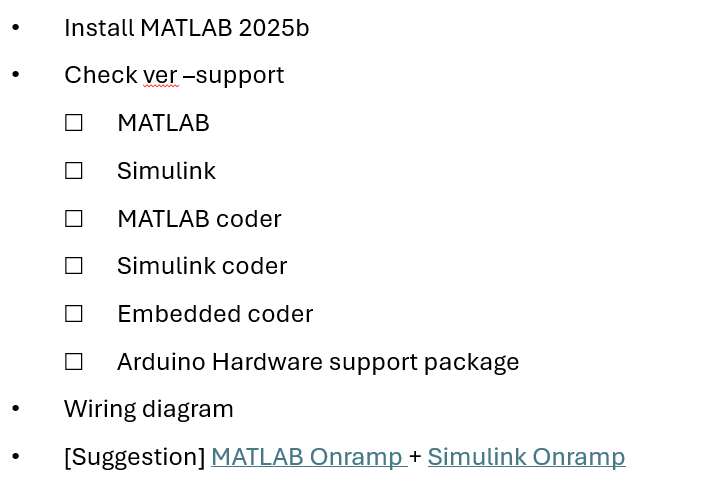

### Instruction files: 

 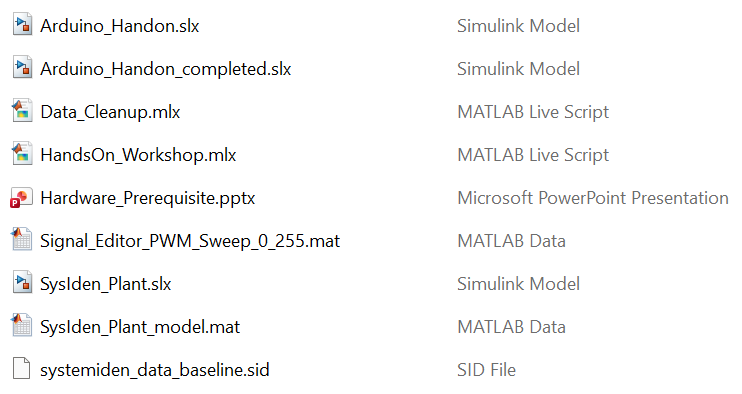

### Wiring Diagram

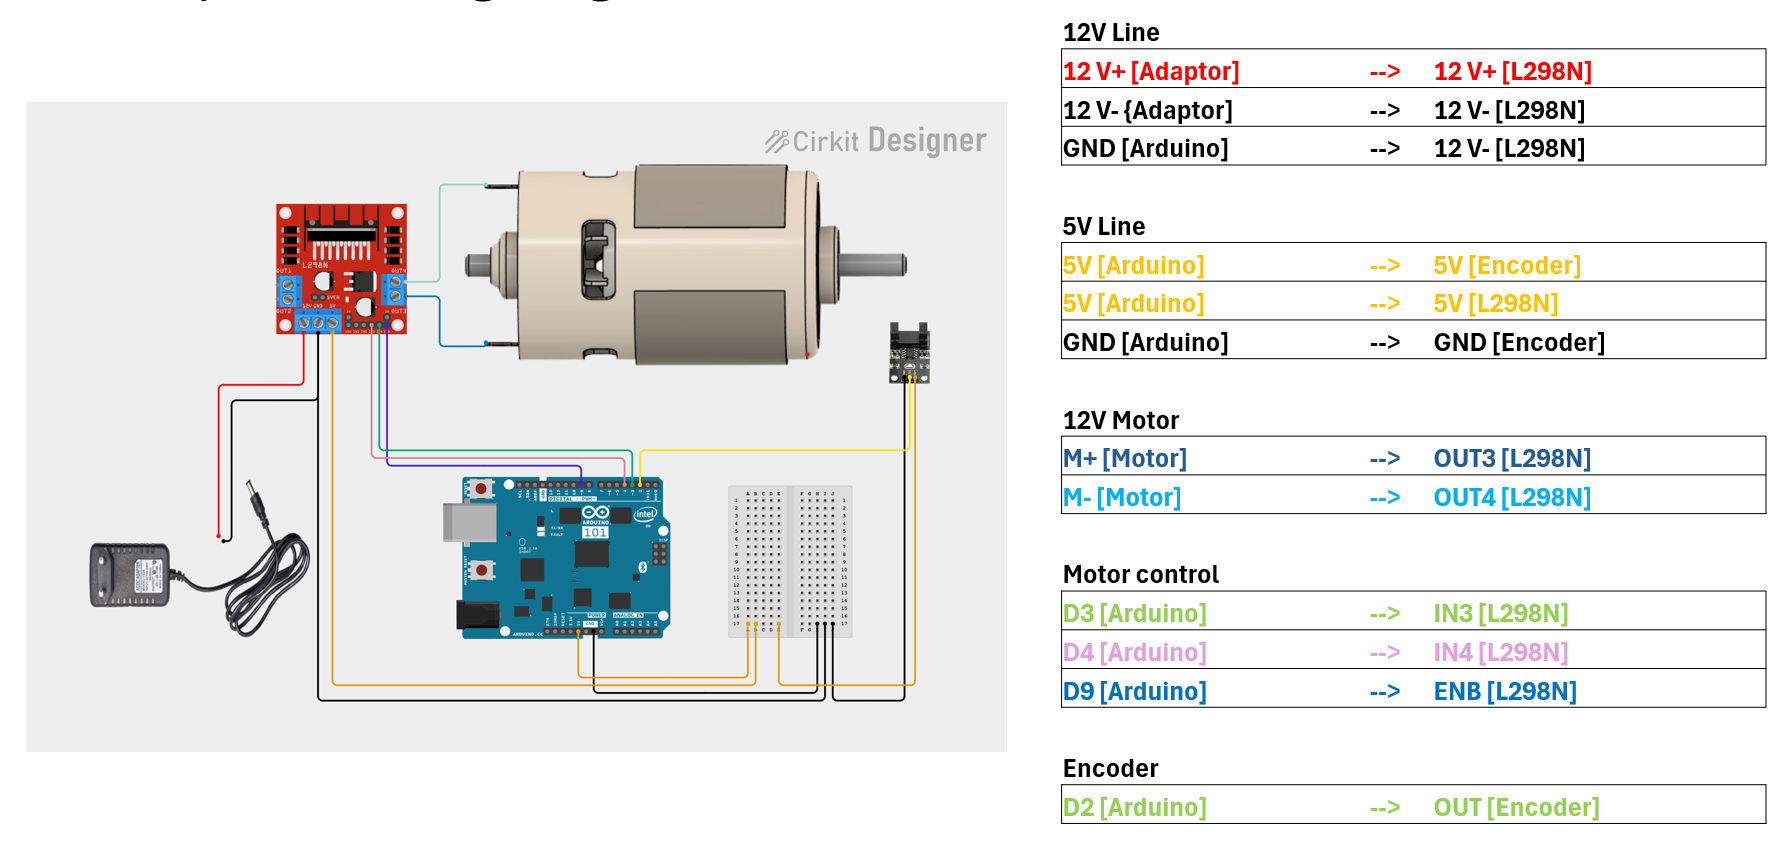

## Introduction to MATLAB

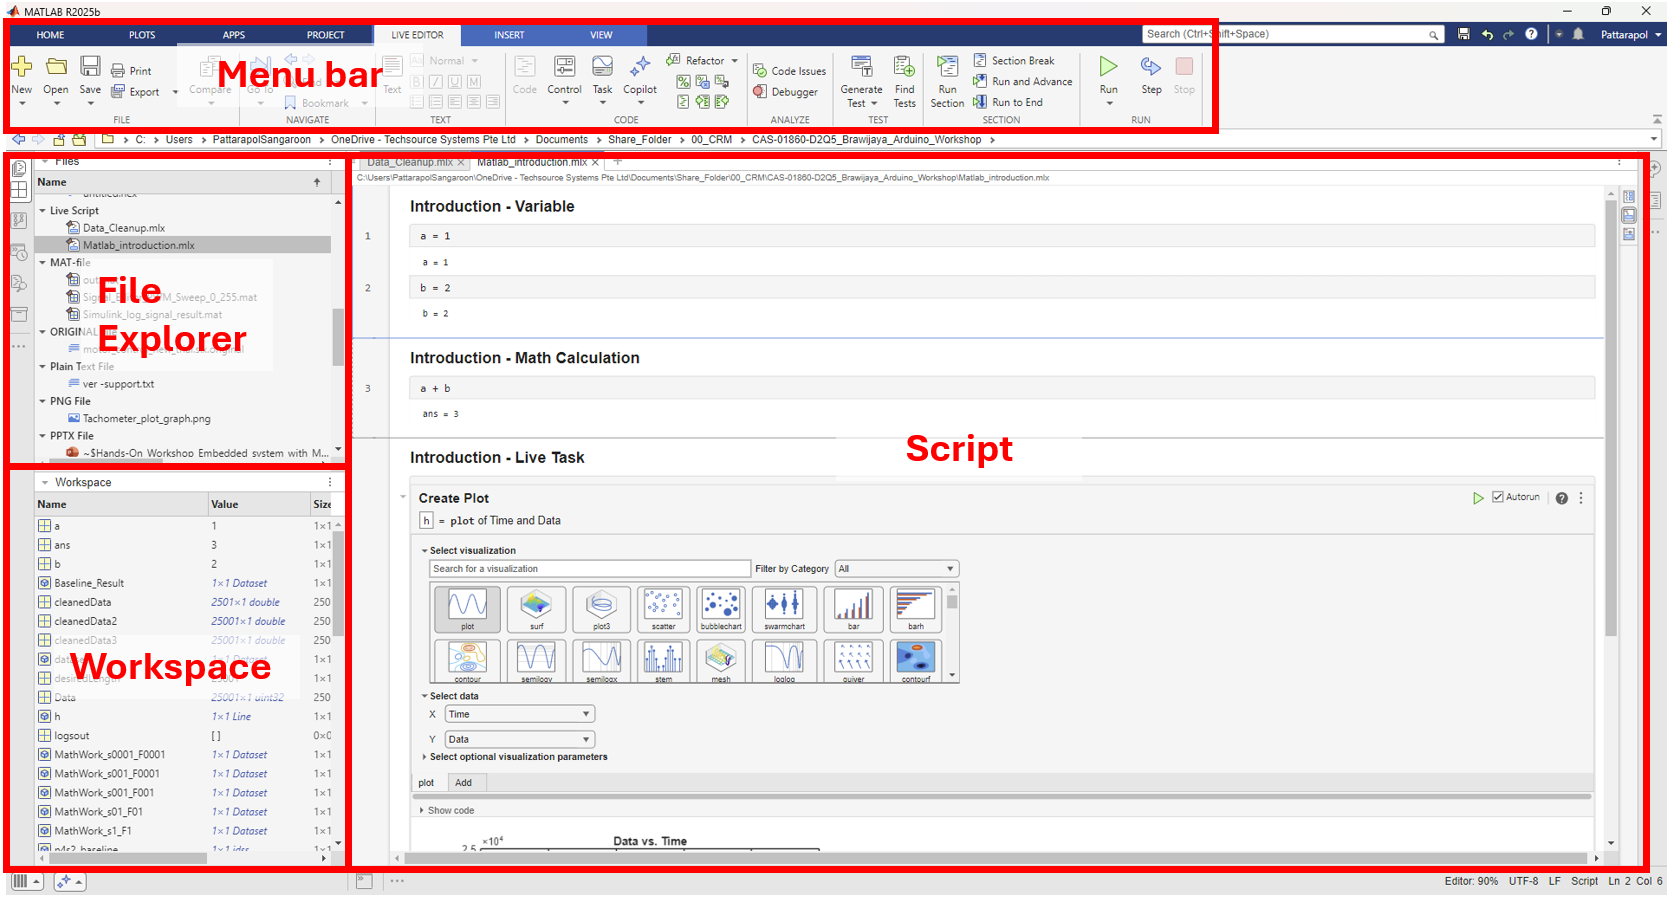

### Menu bar

### 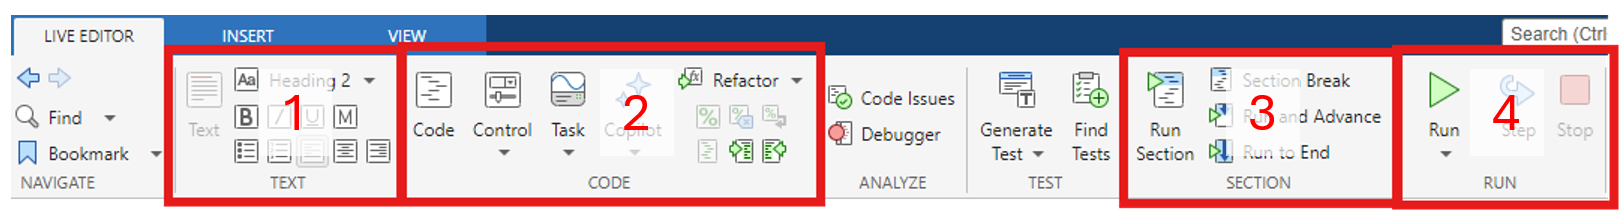

- **TEXT -** Text editor tools ex. Style, Bold, Italic, Bullet

- **CODE -** Code editior tools ex. Code section, Control button, Live Task

- **SECTION -** Section editor tools ex.

- **RUN -** Run entire code, Step in-out, Stop

### Task 1: Create variable

- Create 1st variable "a = 1"

- Create 2n variable "b = 2"

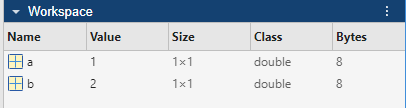

a = 1
b = 2

### Task 2: Math calculation + Call built-in function

- Calculate "result = a + b"

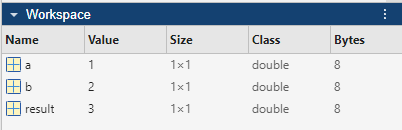

result = a + b

- Call function linspace "series = linspace(0,10, 5)"

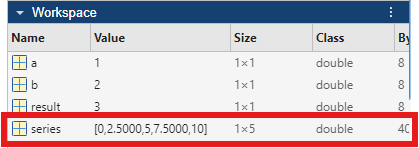

series = linspace(0,10, 5)

### Task 3: Live script and Live Task

- Go to "Task" --> "Create plot"

 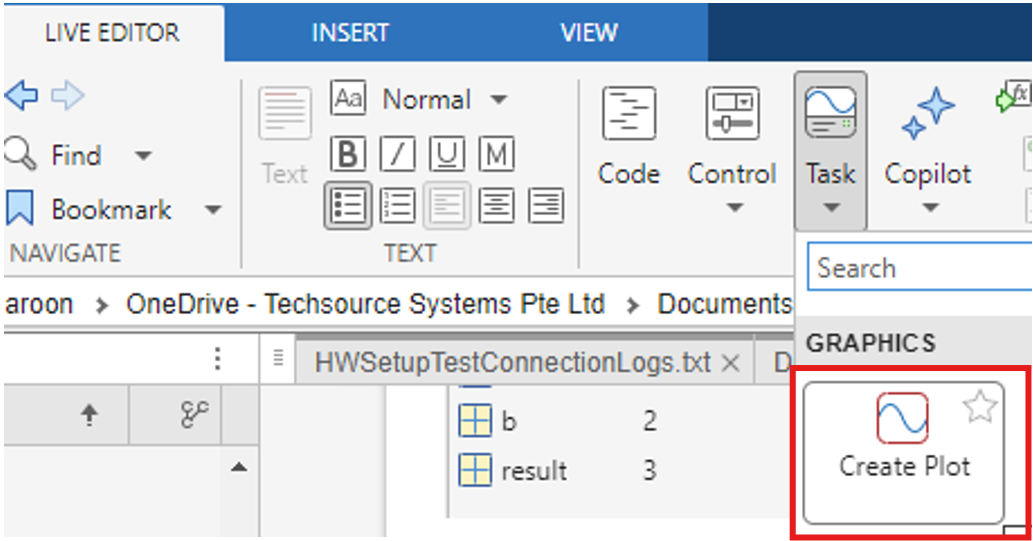

- Select visualization "**Plot**"

- Select data "**Y = series**"

 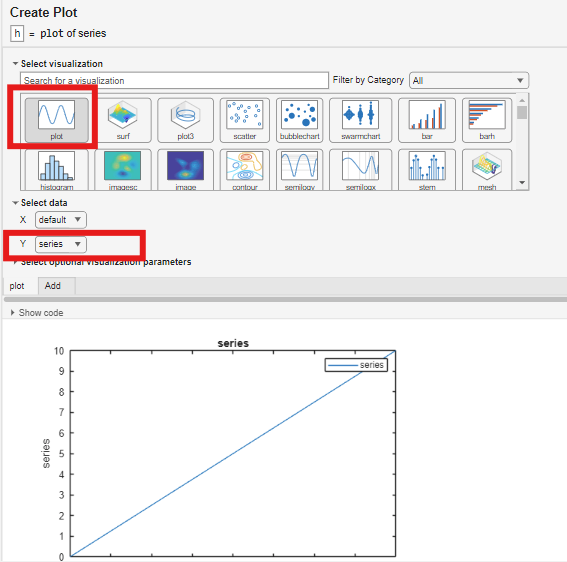

% Create plot of series
h = plot(series,"DisplayName","series");

% Add ylabel, title, and legend
ylabel("series")
title("series")
legend

## Introduction to Simulink

### Simulink

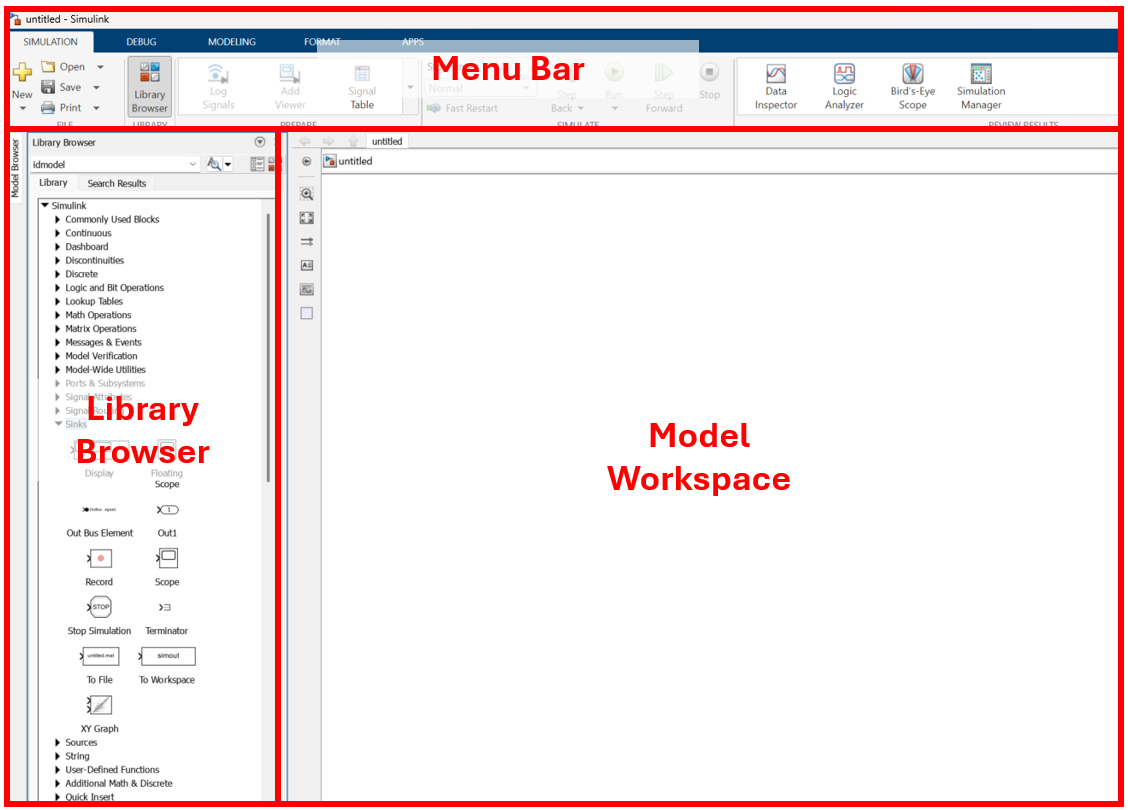

### Task 4: Simulink block and Simulation

- Drag and Drop "**Sine Wave**" block from "**Simulink>Sources**" to the workspace

- Drag and Drop "**Scope**" block from "**Simulink>Sink**" to the workspace

- Connect the signal from "**Sine Wave**" to "**Scope**" 

 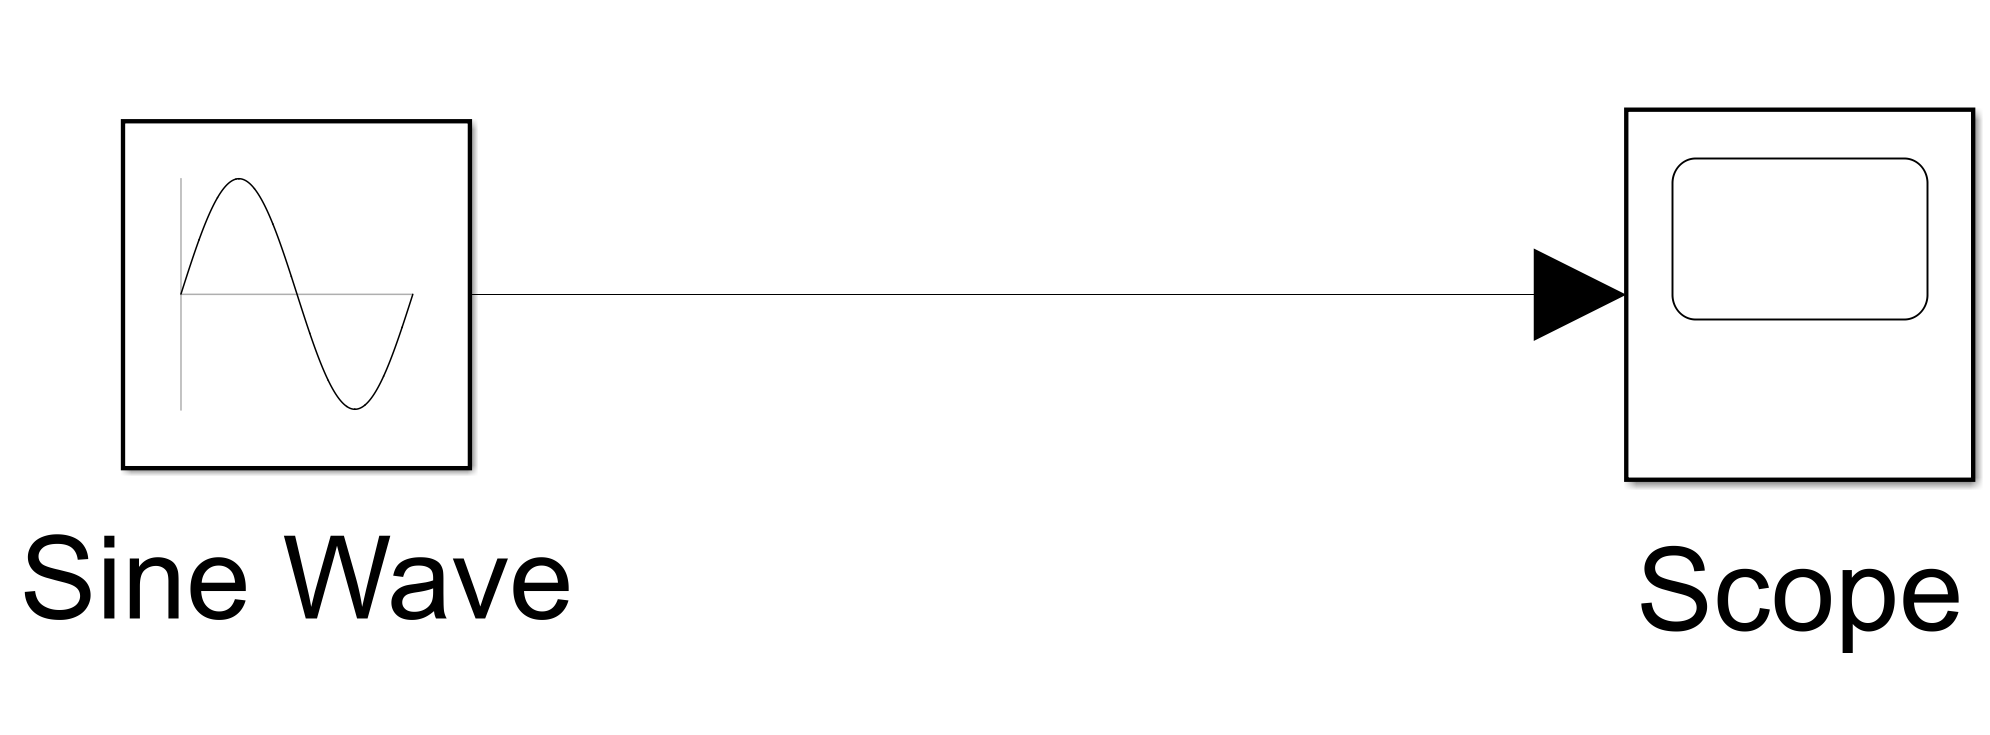

- Start simulate the system by clicking "**Run**" at Simulate section

 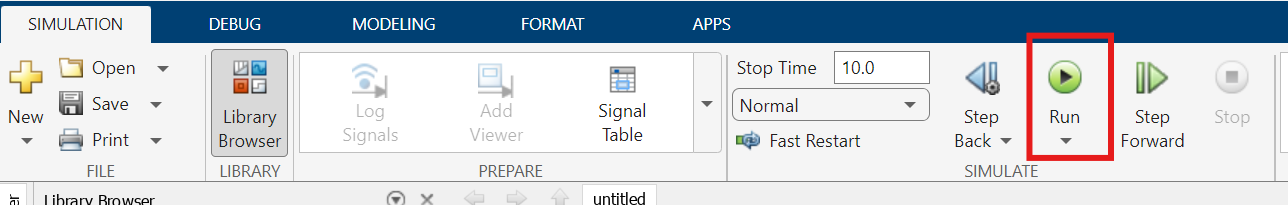

- Check the output by double click at "**Scope**"

 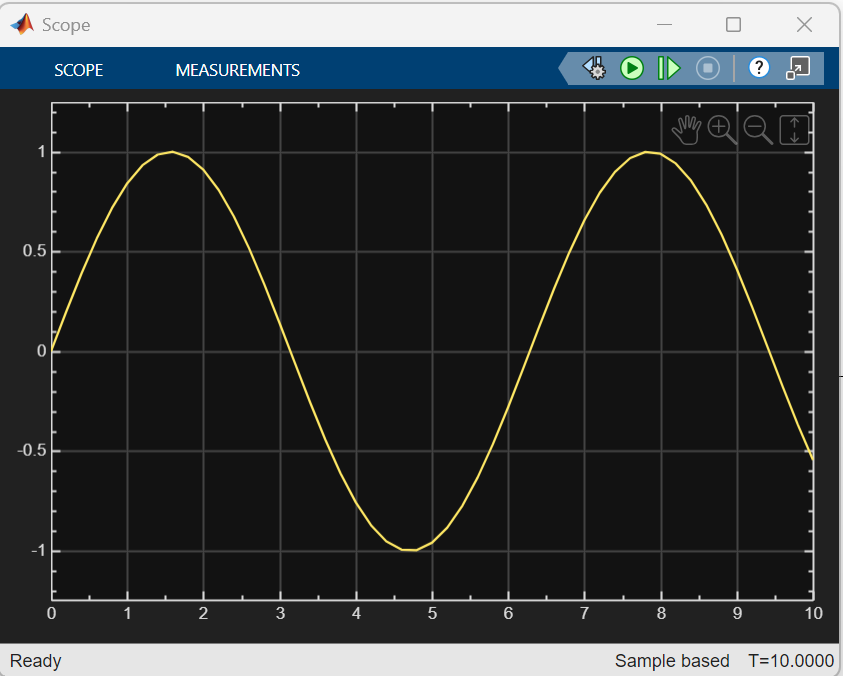

### Task 5: Math calculation

- Drag and Drop "**Gain**" block from "**Simulink>Math Operations**" to the workspace

- Place the "**Gain**" block in the signal line between "**Sine Wave**" and "**Scope**" block 

 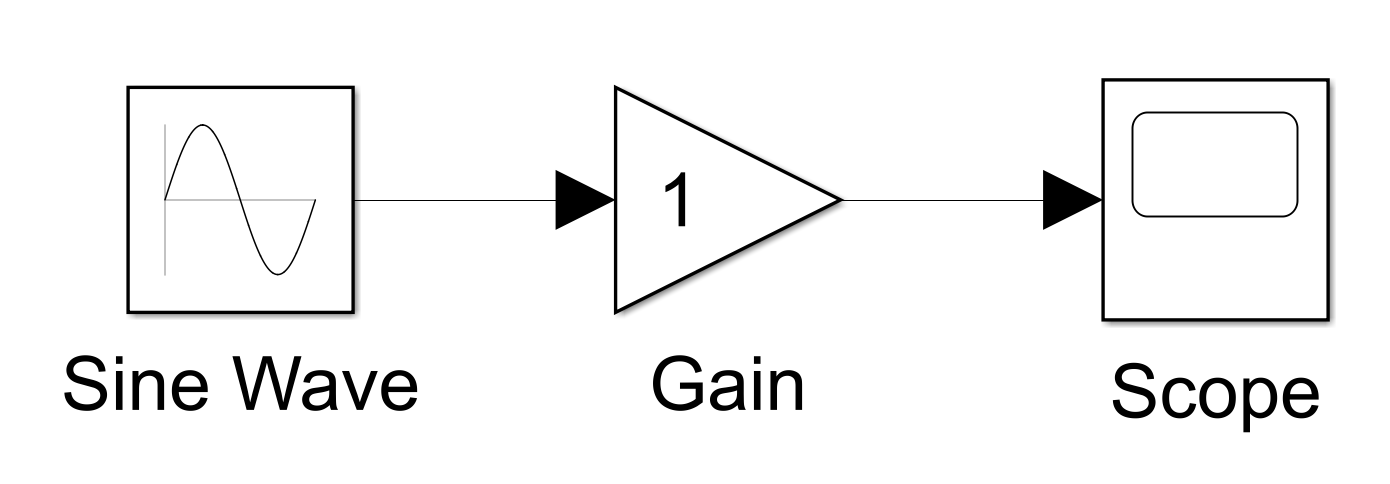

- Double click at "Gain" block and Change the gain value to 2

 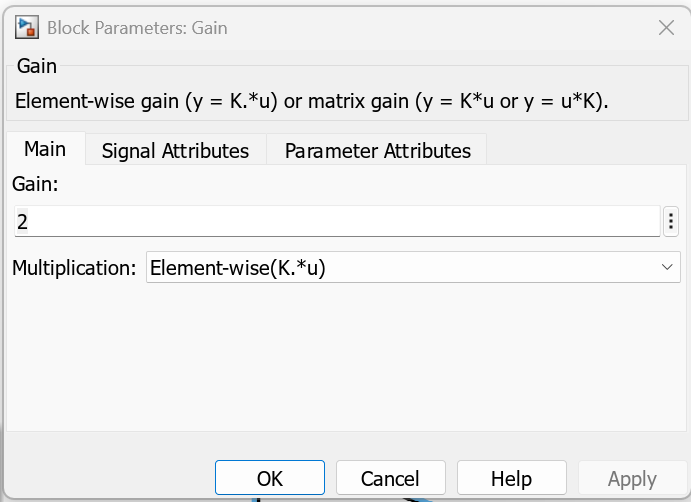

- Start simulate the system by clicking "**Run**" at Simulate section

- Check the output by double click at "**Scope**"

 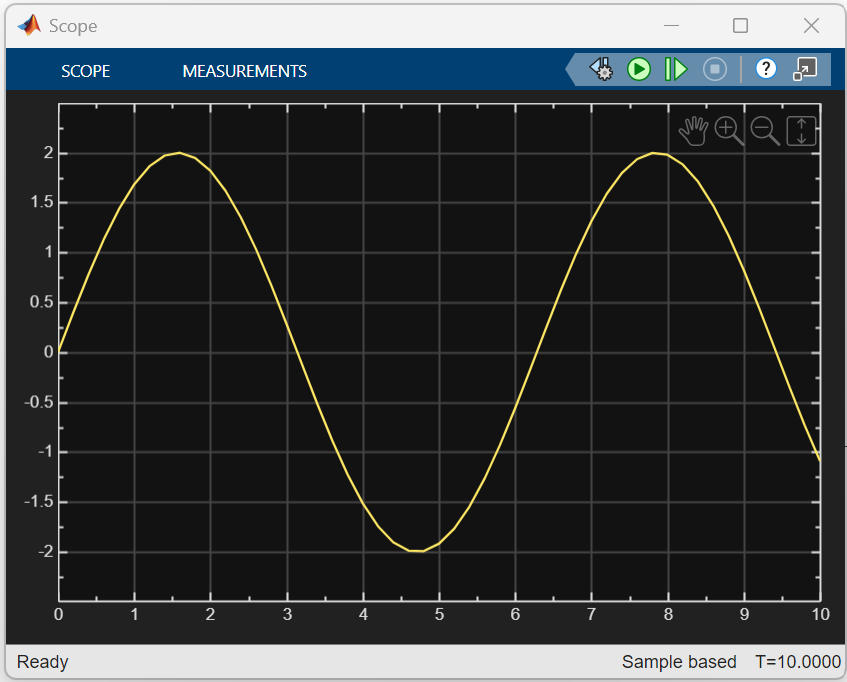

### Task 6: Dashboard control

- Drag and Drop "**Slider**" block from "**Simulink>Dashboard**" to the workspace

 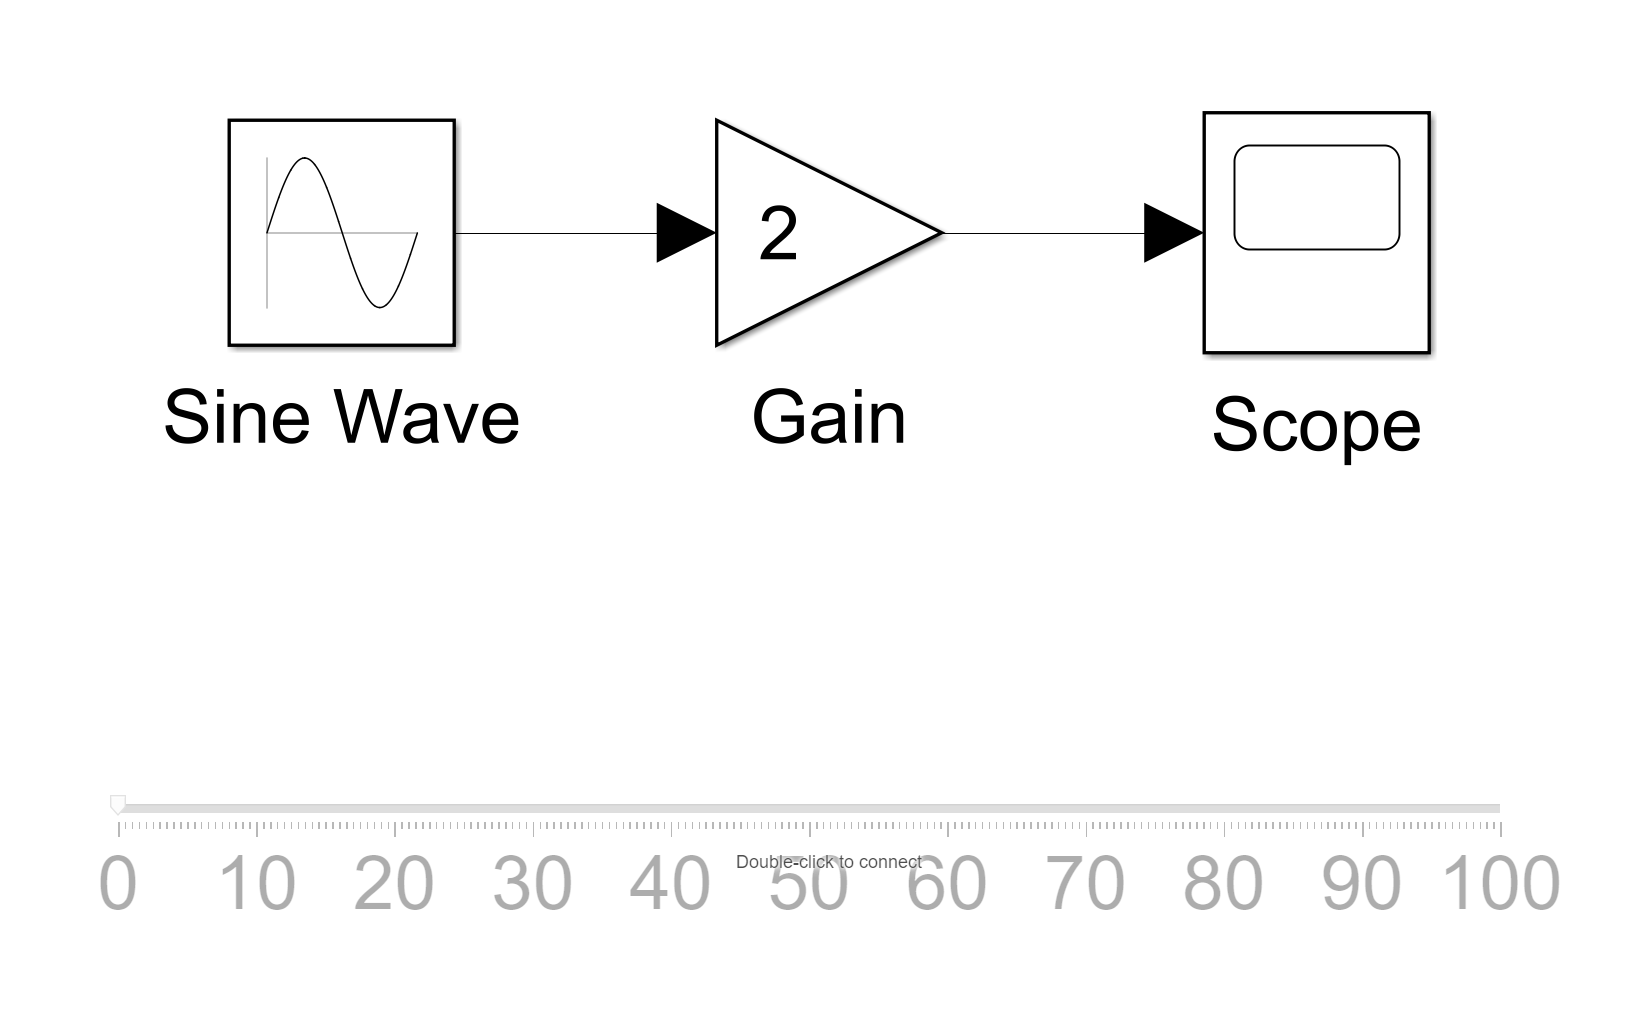 

- Double click at "**Slider**" --> Select "**Gain**" block --> Click at "**Connect**" check of the gain value --> Click "**OK**" to confirm

 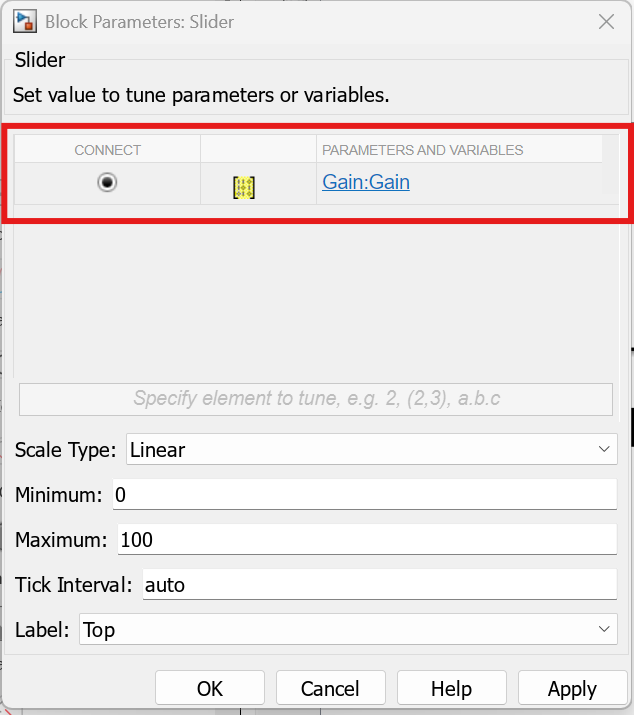

- Change "**Stop Time**" to "**Inf**"

 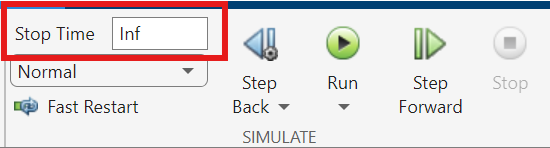

- Try to Slide the "**Slider**" bar and see the changed of Sine Wave at "**Scope**"

 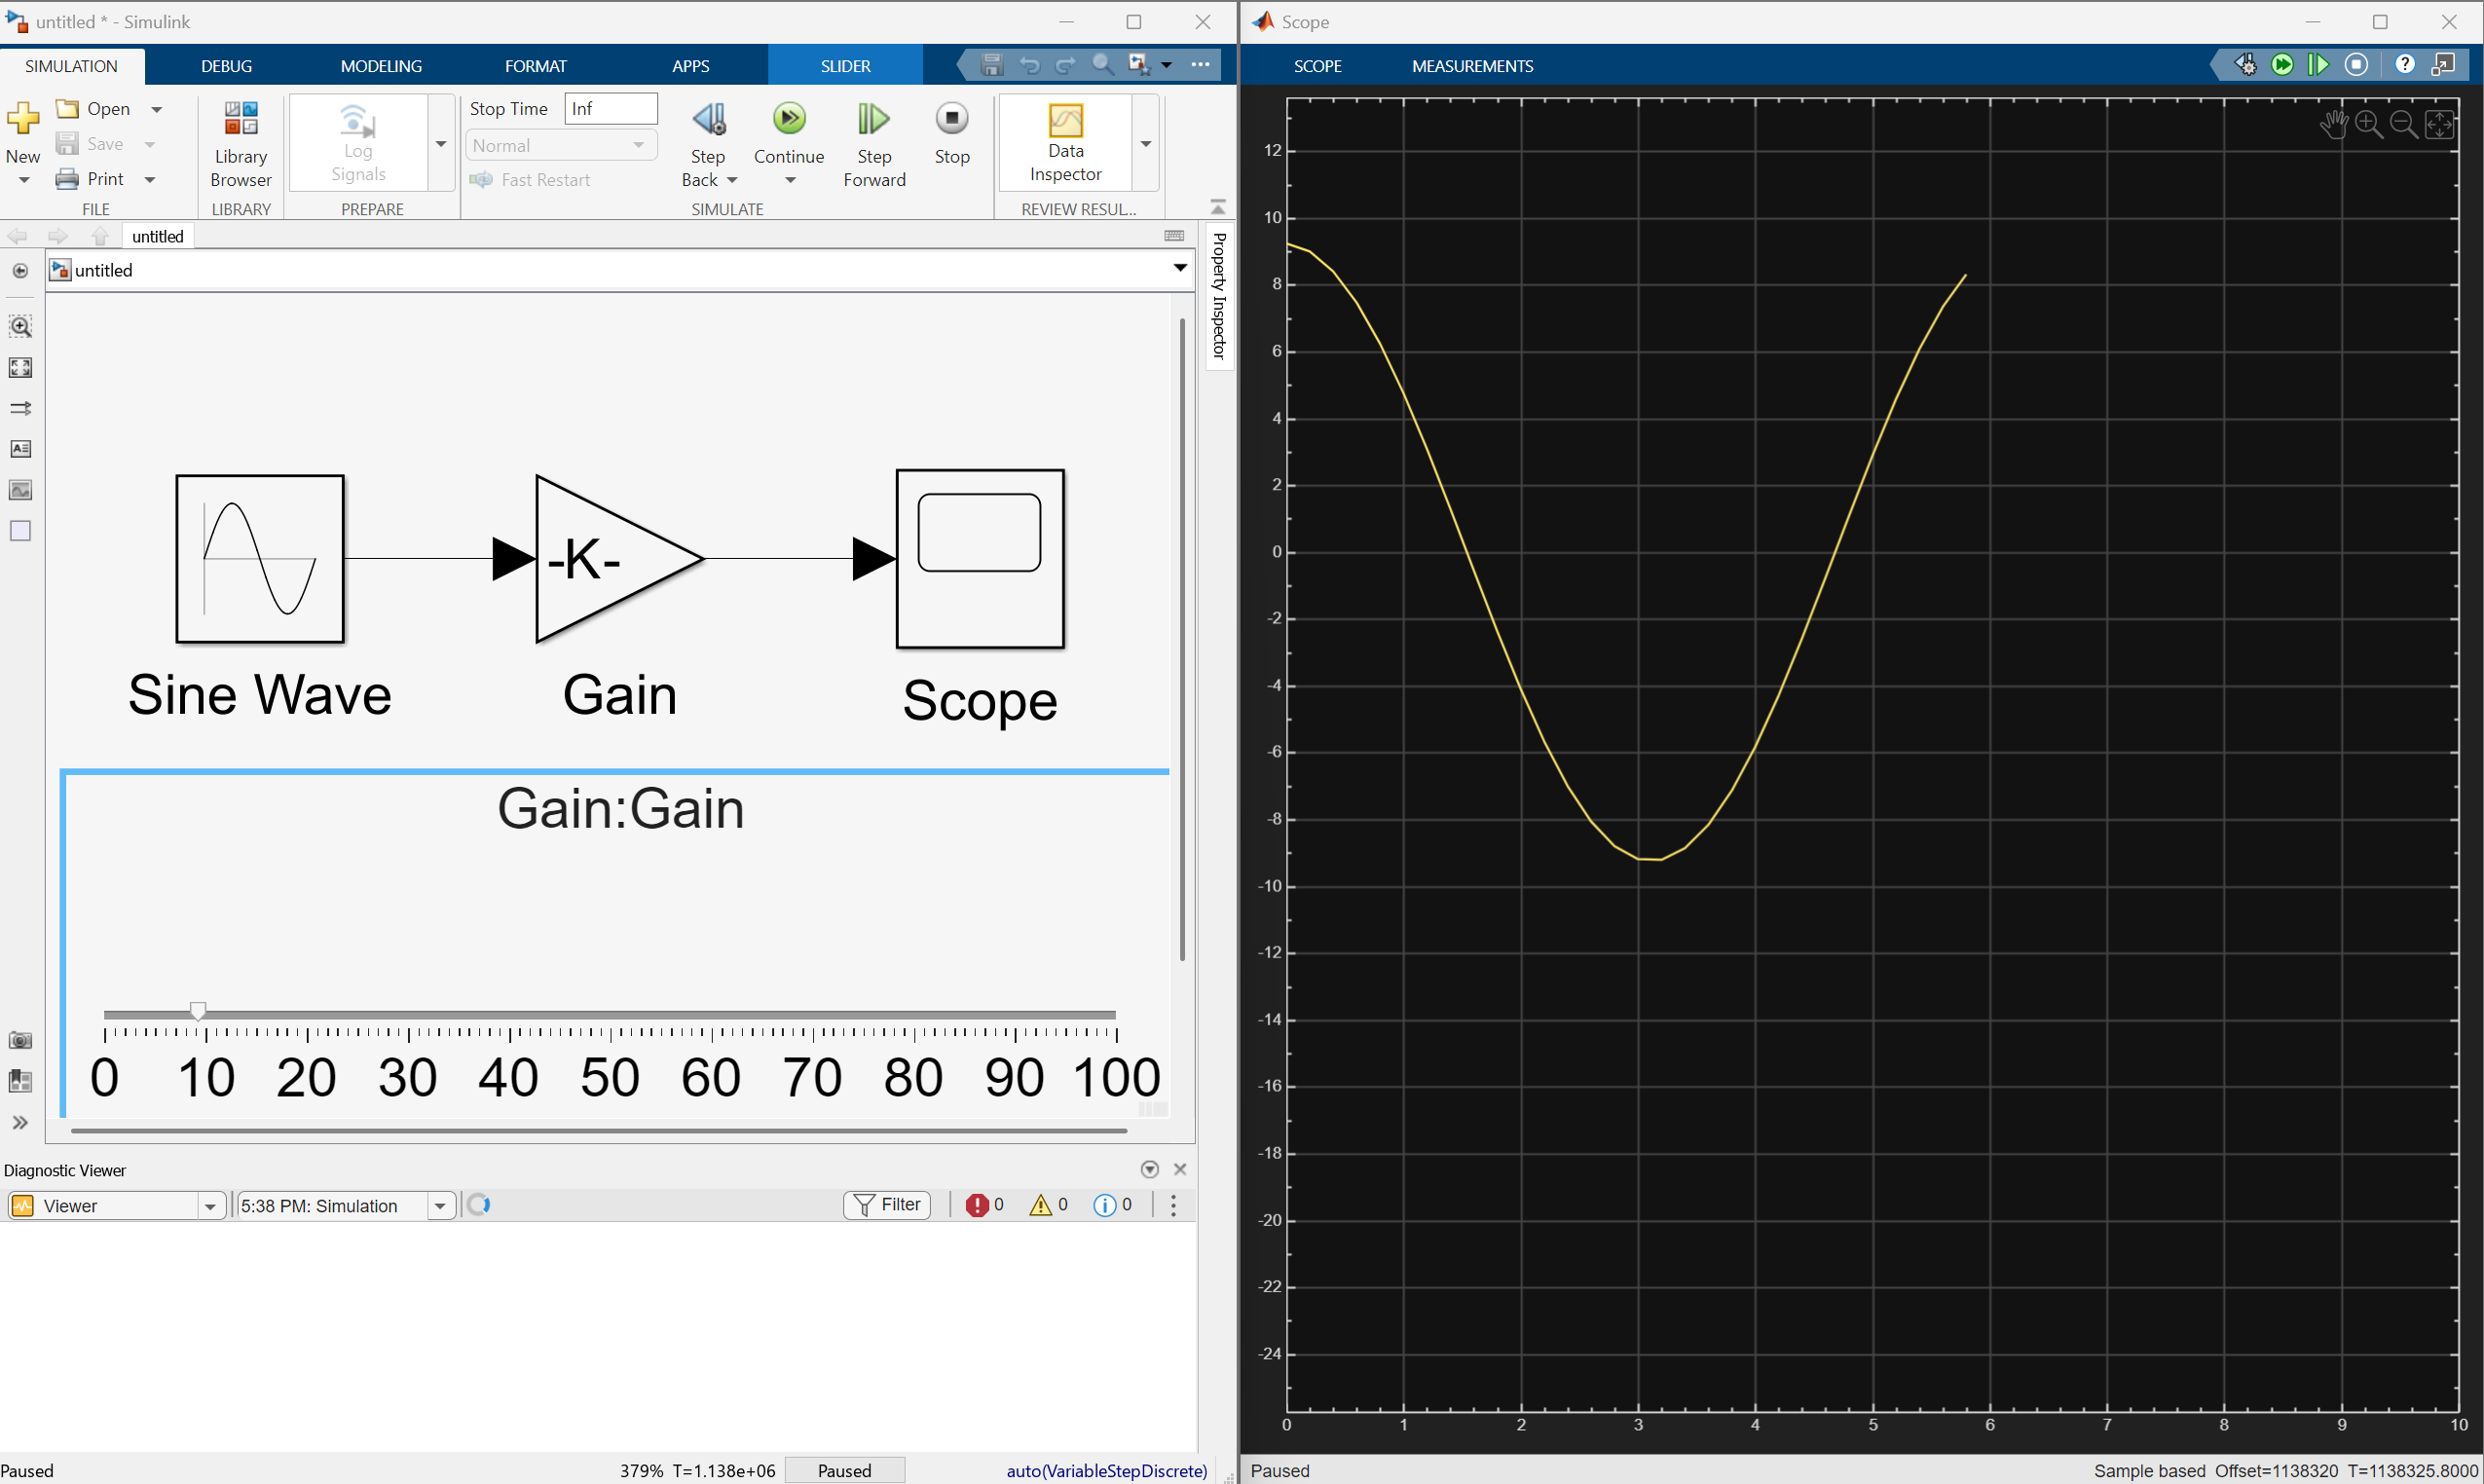

## Simulink with Embedded system [Arduino]

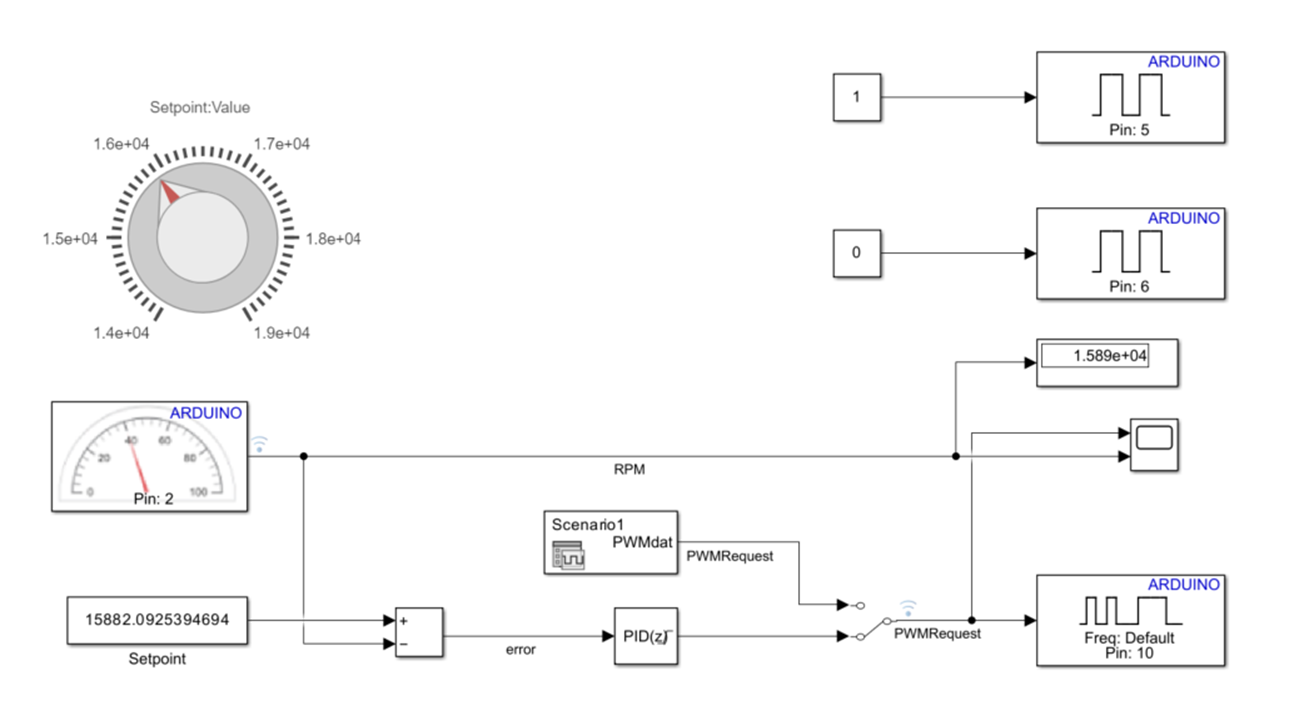

### Task 7: Arduino Hardware support

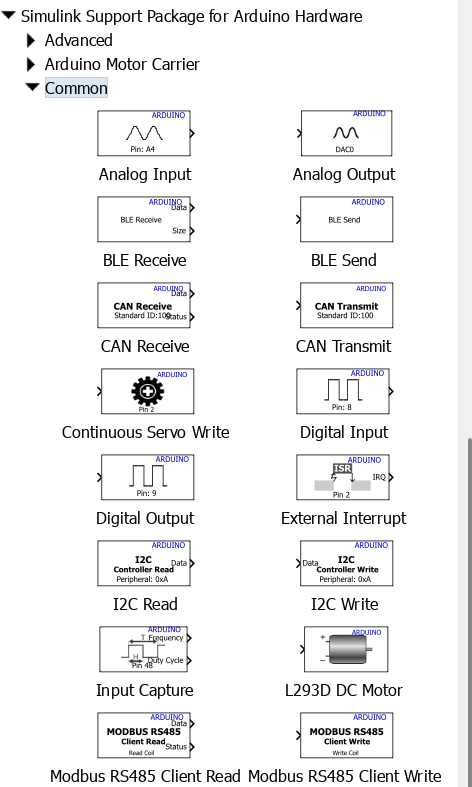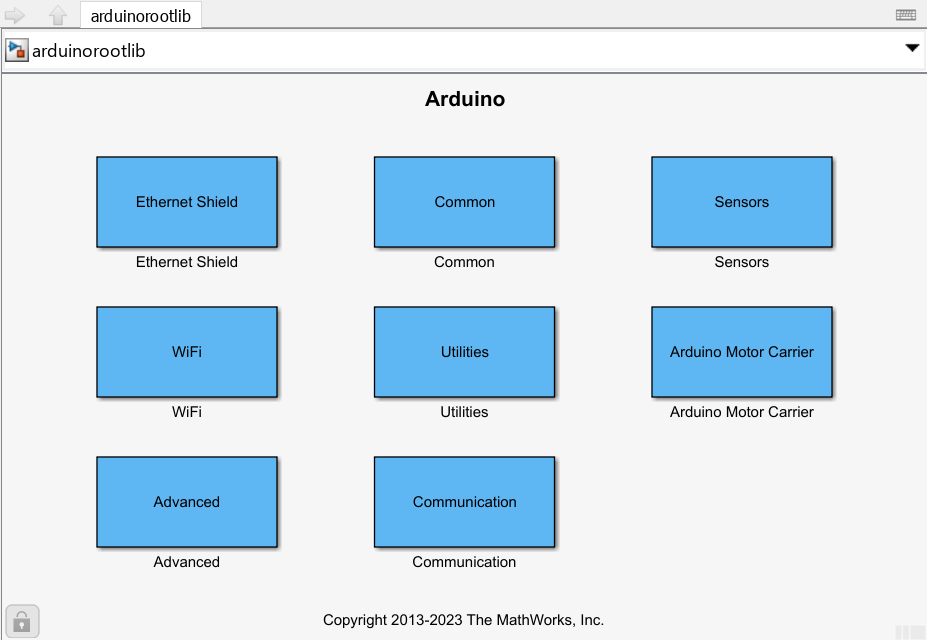

#### Digital Output

- Drag and Drop "**Digital Output**" 2 blocks from "**Simulink>Simulink Support Package for Arduino Hardware>Common**" to the workspace

- --> Set output pin of "**Digital Output**" to 3 and 4 respectively --> Create "**Constant**" block value "**0**" and "**1**" and sending to those "**Digital Output**" respectively

 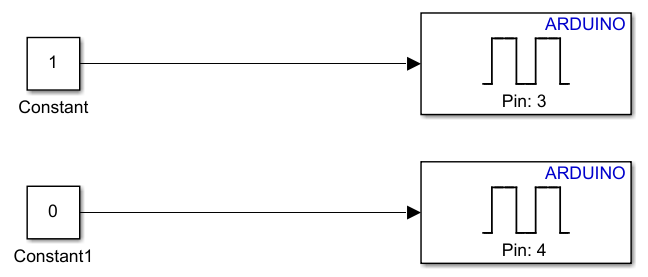

#### Tachometer

- Drag and Drop "**Tachometer**" 2 blocks from "**Simulink>Simulink Support Package for Arduino Hardware>Sensors**" to the workspace

- --> Set "Pulse count per rotation" to "**20**" and "Sample time" to "**0.01**" connect the output to "**Scope**" and "**Display**" block

 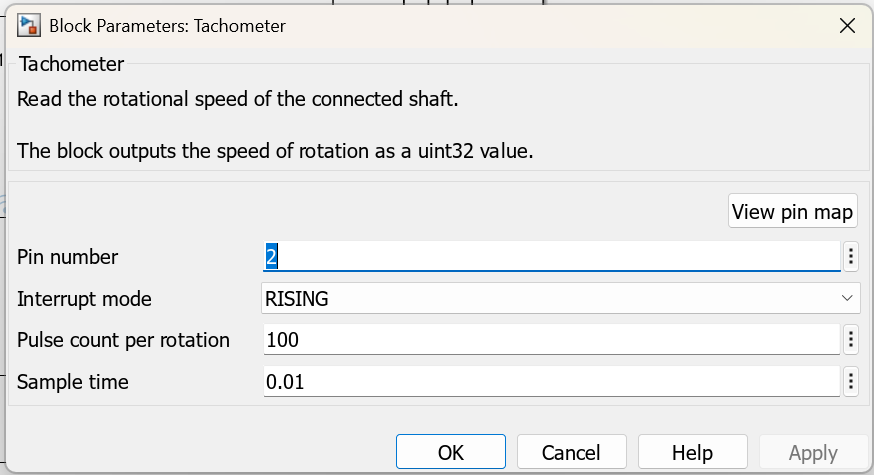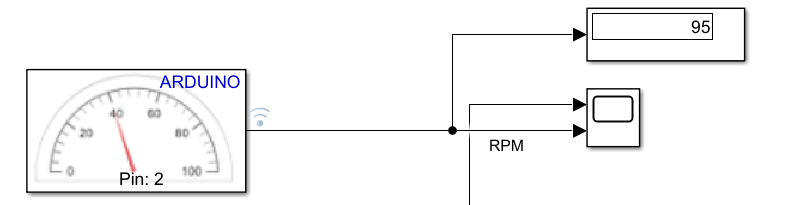

#### PWM

- Drag and Drop "**PWM**" blocks from "**Simulink>Simulink Support Package for Arduino Hardware>Common**" to the workspace

- --> Set "**Pin number**" to "**9**" and Create constant value "**150**" to be the input for "**PWM**" block

- Route signal from constant to be the another input to "**Scope**" to see the output comparison between "**PWMRequest**" and "**RPM**"

 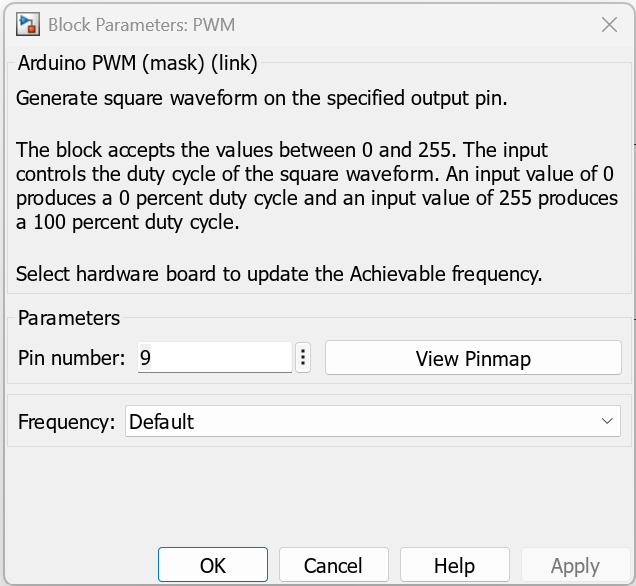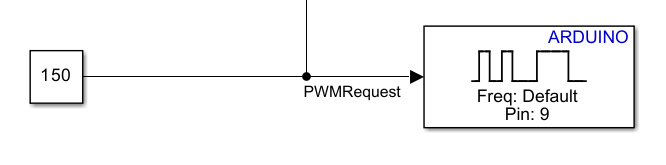

- Start simulate the system by clicking "**Run**" at Simulate section

- Check the output by double click at "**Scope**"

 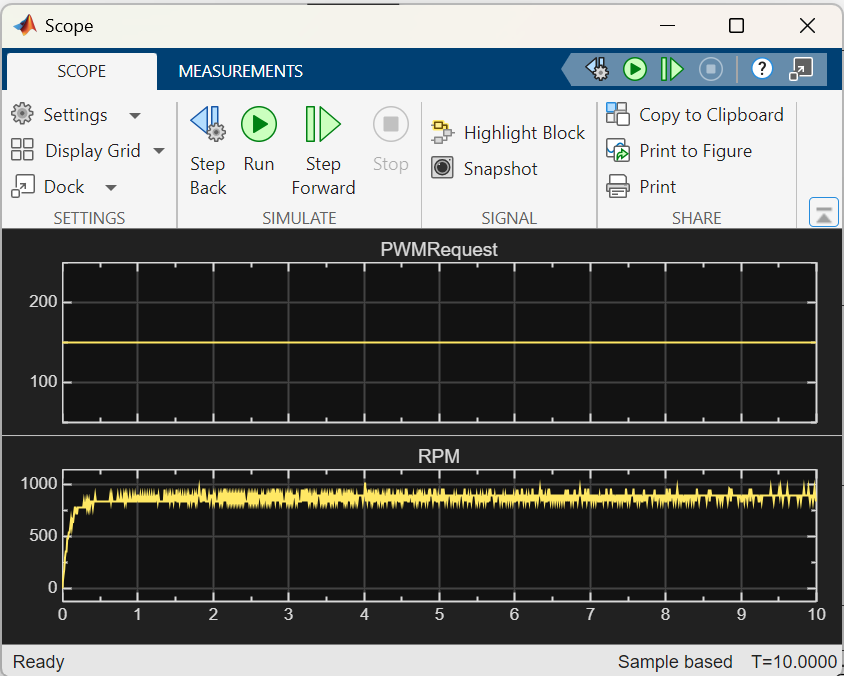

### Task 8: Test pattern with Signal Editor and Collect data

- Drag and Drop "**Signal Editor**" block from "**Simulink>Source**" to the workspace

- Drag and Drop "**Manual Switch**" block from "**Simulink>Signal Routing**" to the workspace

- Connect "**Signal Editor**" and Previous PWM's "**Constant**" to "**Manual Switch**" --> Connect output of "**Manual Switch**" to be the input of "**PWM**" block from previous task

 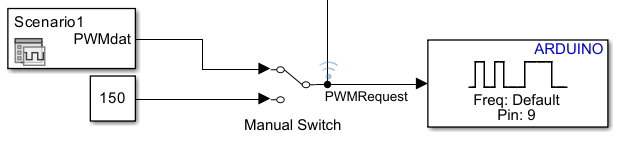

- Edit paramter in "**Signal Editor**"

- Set "**File name**" to the provided file "**Signal_Editor_PWM_Sweep_0_255.mat**"  and "**Active Scenario**" to "**Scenario 1**"   

        *You can view the test pattern by clicking the icon in Blue square which will open the Signal Editor window that allow you to view, modify and create any signal pattern

 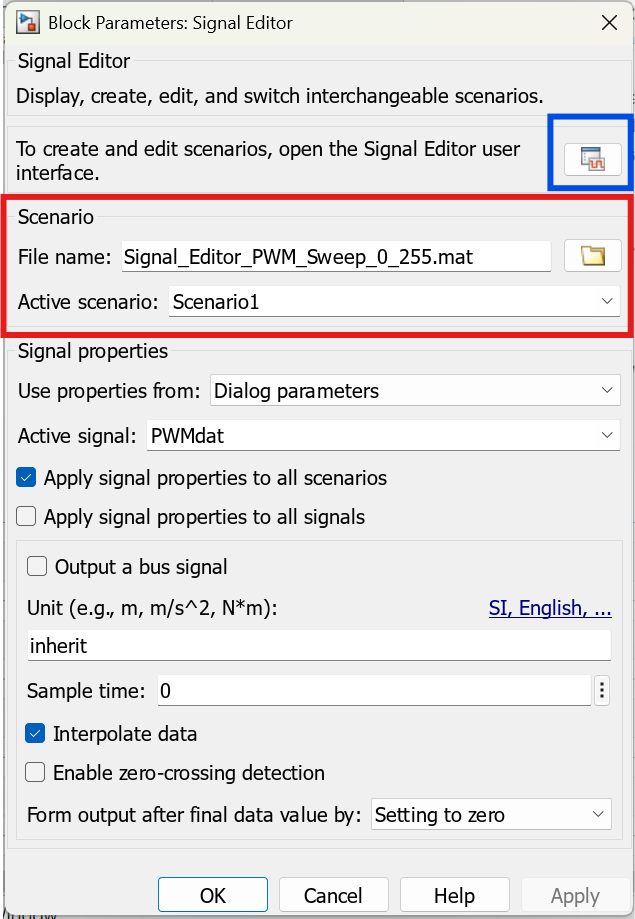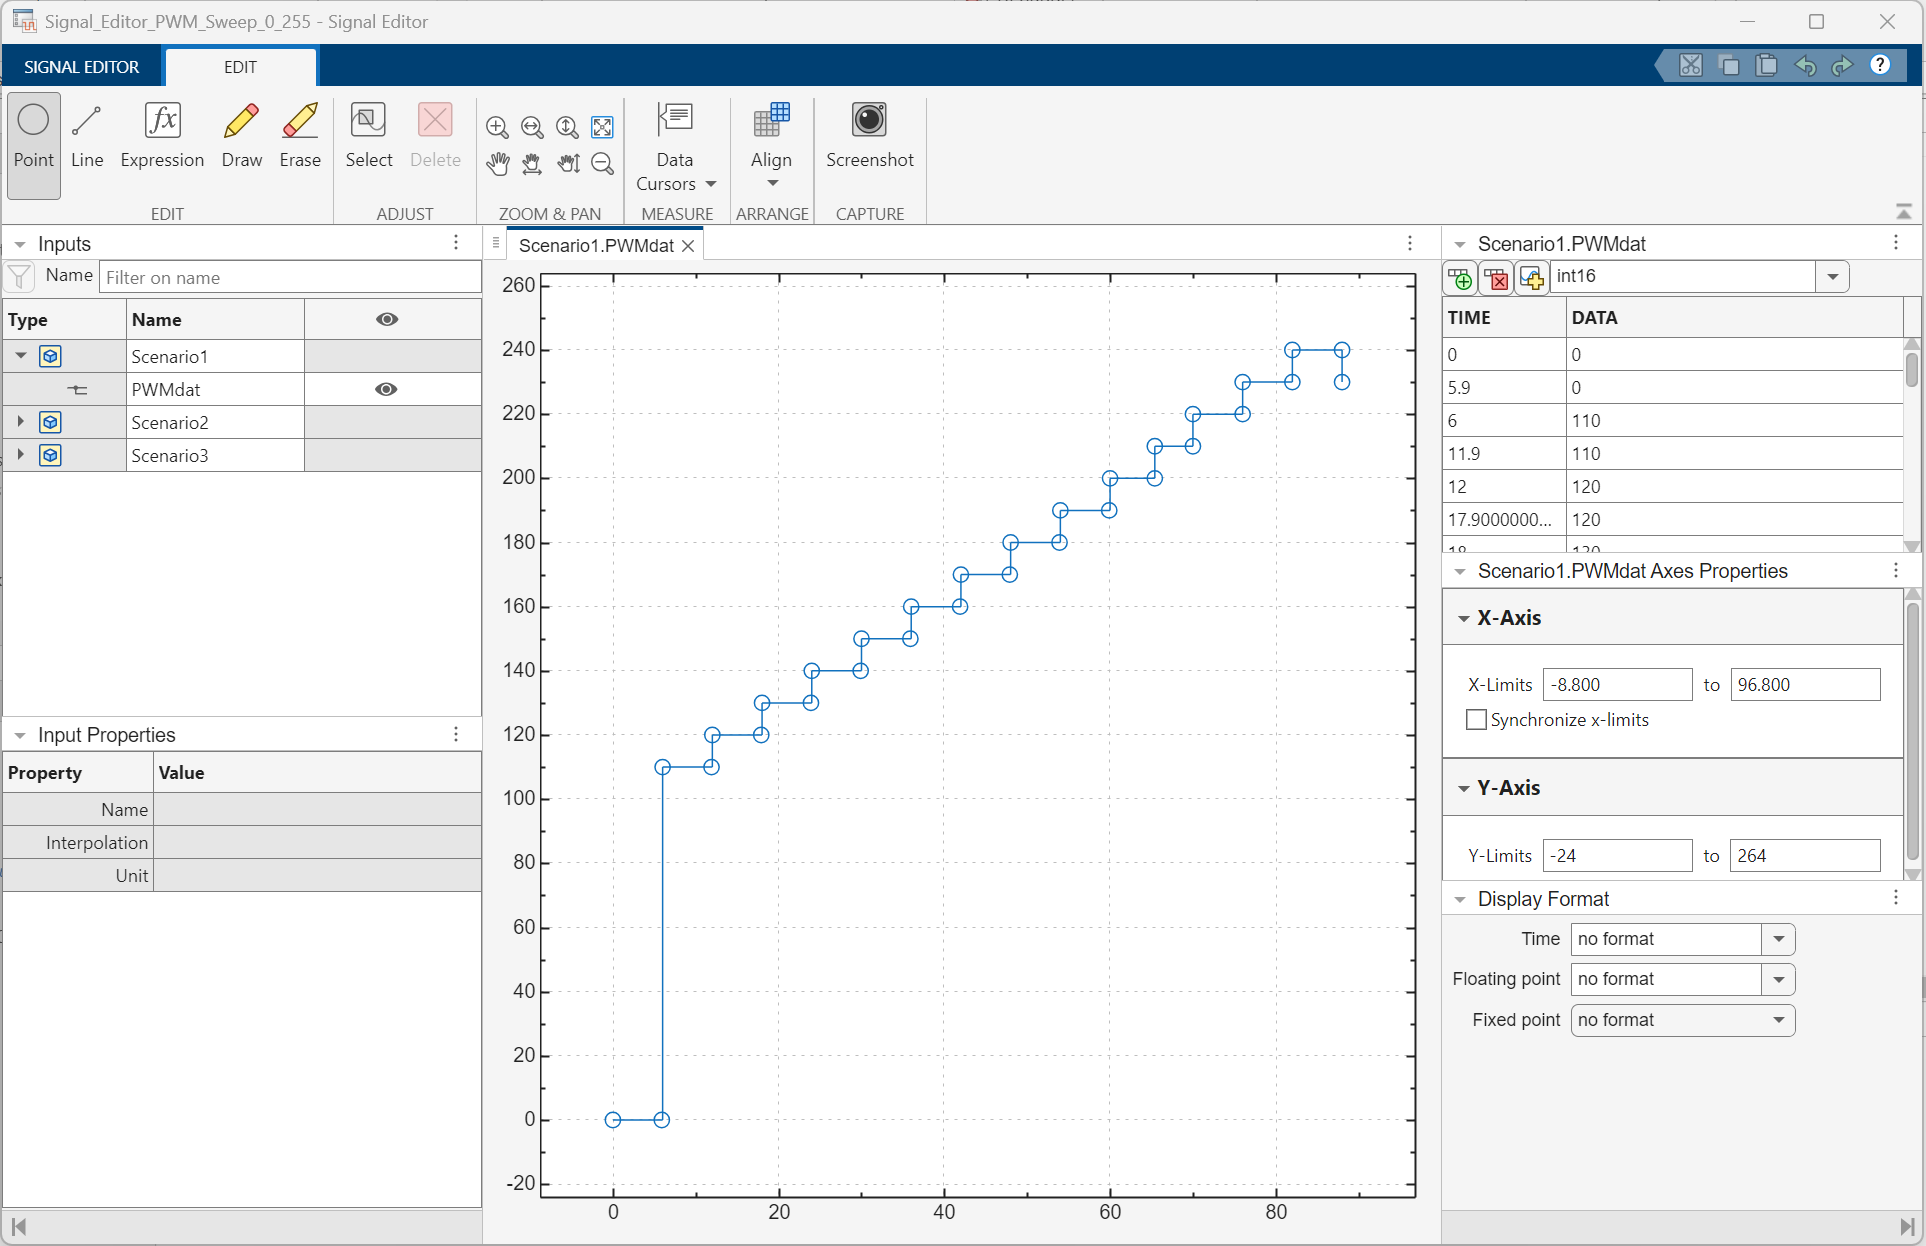

- Log the Signal using "**Log Signals**" function by highlight "**PWMRequest**" and "**RPM**" signal --> Go to Signal Tab --> Check "**Log Signal**" **This action will all the system to log the data and enable use to view the data in "****Data Inspector****"*

- Start simulate the system by clicking "**Run**" at Simulate section

- Check the output by double clicking at "**Scope**"

- Check the logged output by clicking at "**Data Inspector**" 

 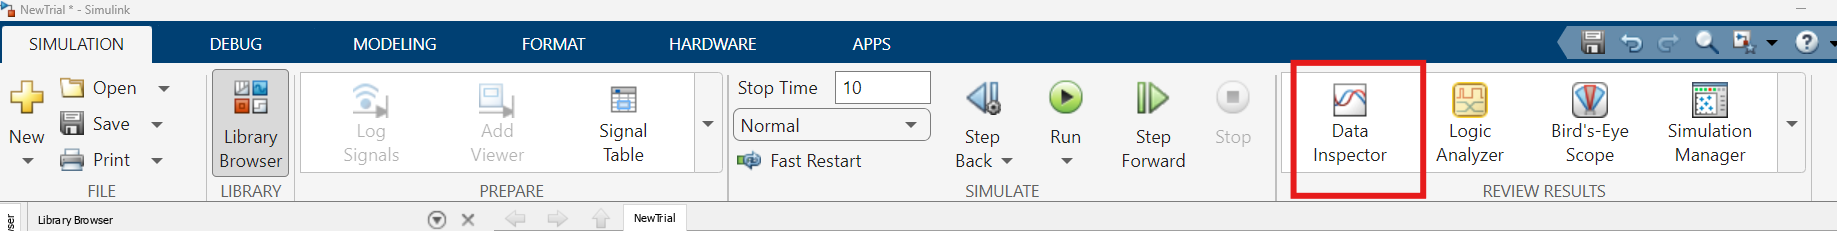

 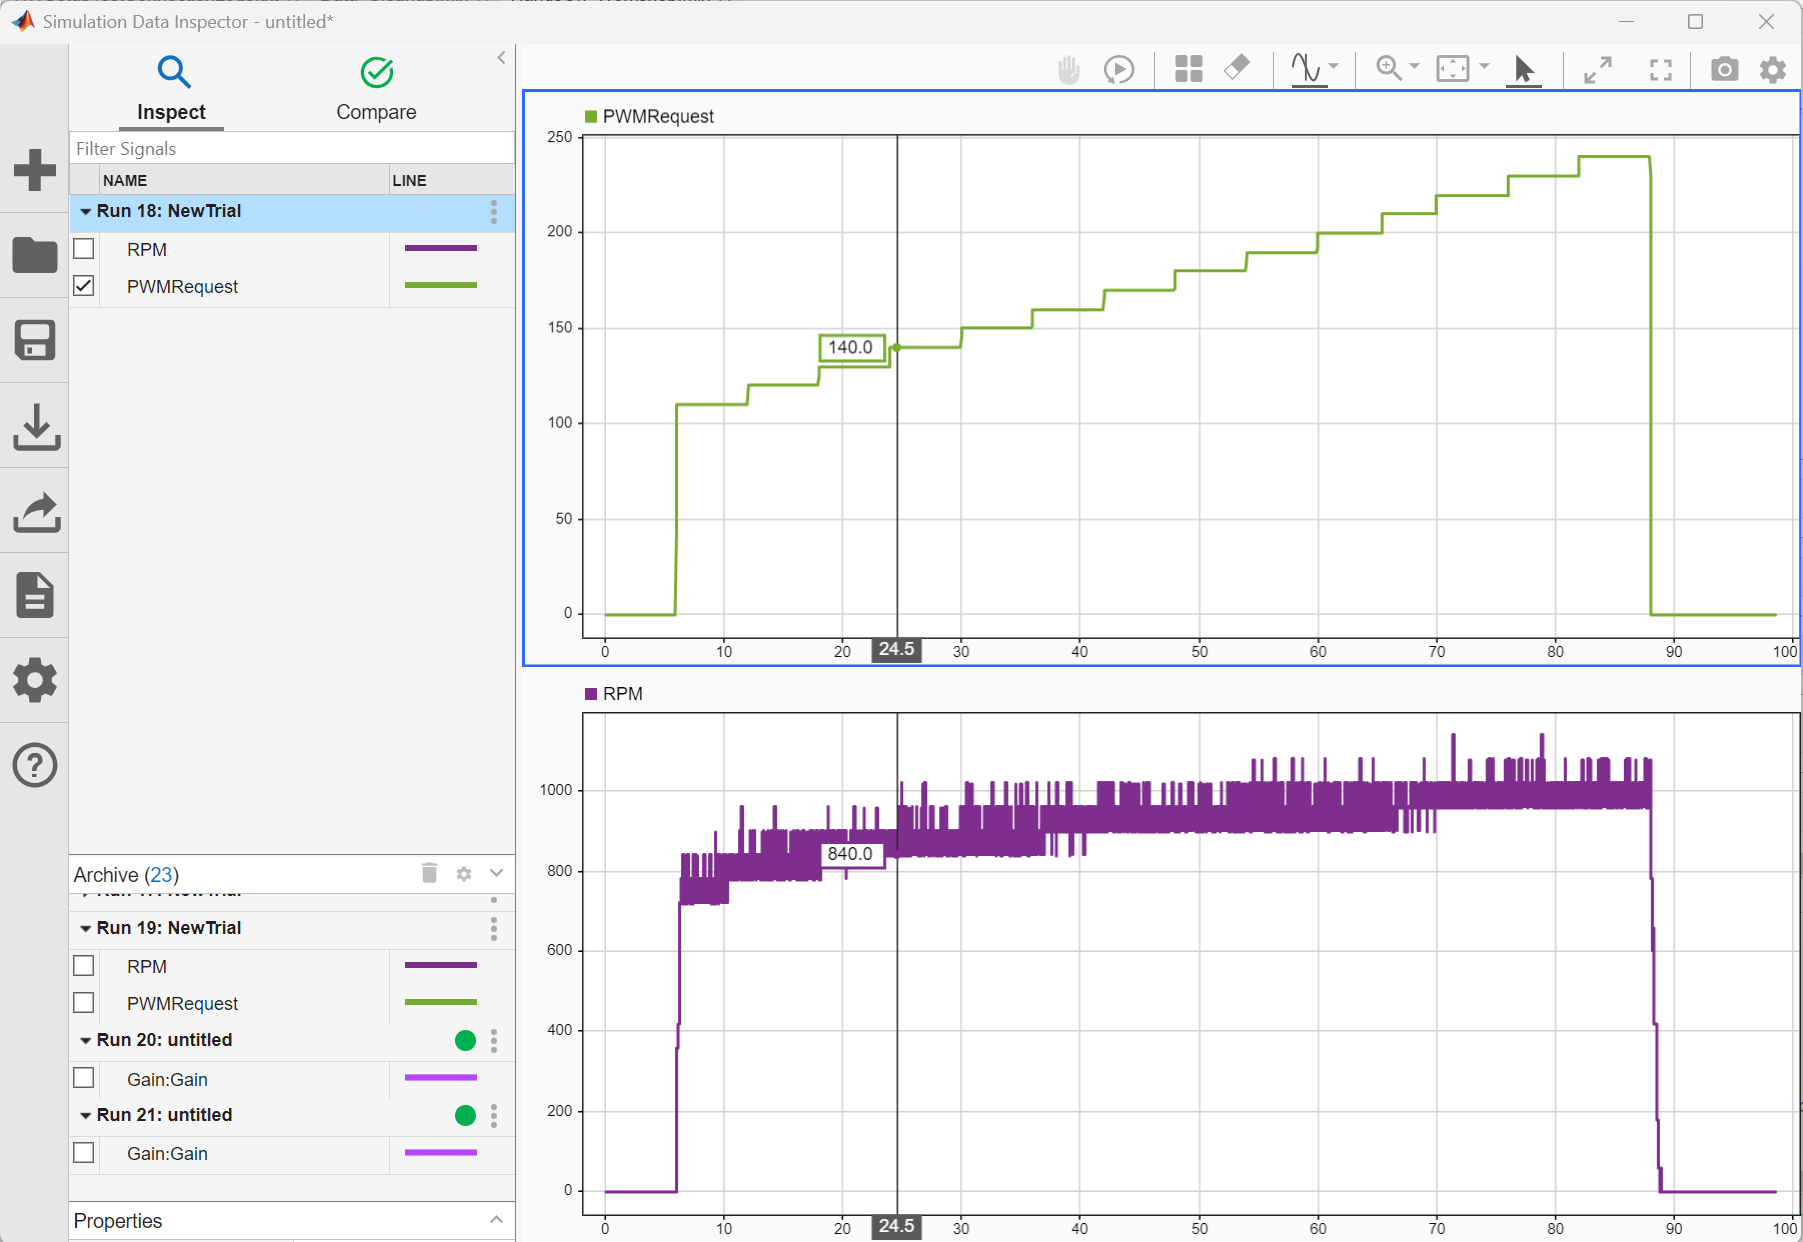

- Export the log result by Highlight signals data and Right click --> Export --> Base workspace **The result will be exported to MATLAB workspace ready for next process* 

 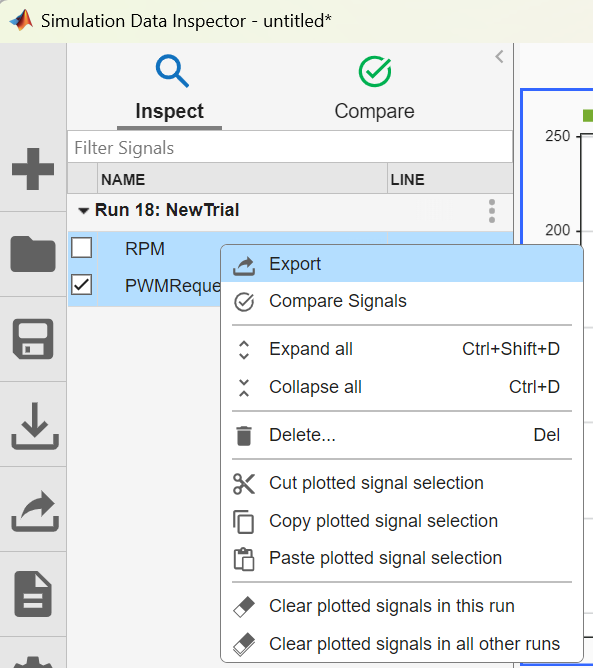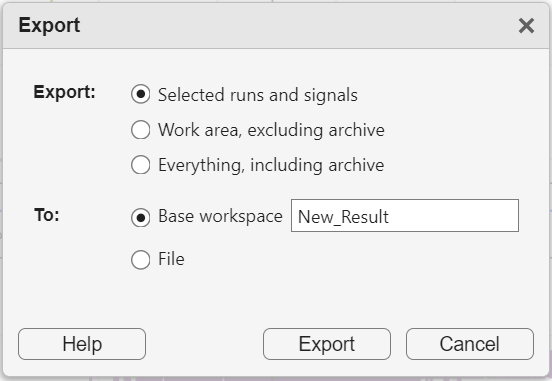

### Task 9: PID control

- Drag and Drop "**Discrete PID Controller**" block from "**Simulink>Discrete**" to the workspace --> Connect to the "**Manual Switch**" in place of PWM "**Constant block**"

- Drag and Drop "**Subtract**" block from "**Simulink>Math Operations**" to the workspace --> Connect to the input of "**Discrete PID Controller**"

- Create "**Constant**" to be the setpoint for PID controller subtract by RPM reading from "**RPM**" by using "**Subtract**" block

- Drag and Drop "**Knob**" block from "**Simulink>Dashboard**" to the workspace --> Connect to setpoint's "**Constant**" block **This enable us to change the target setpoint during simulation*

 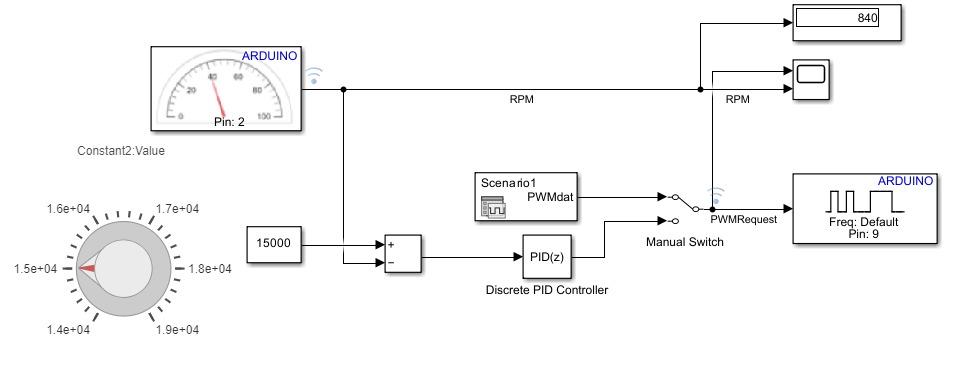

- Start simulate the system by clicking "**Run**" at Simulate section **Try to change the setpoint by varying knob during the simulation to see the response*

- Check the output by double clicking at "**Scope**"

- Check the logged output by clicking at "**Data Inspector**"

open Arduino_Handon.slx

## [Optional] Create Plant modelling 

### Task 10: [Optional] Data Clean up and Preprocessing

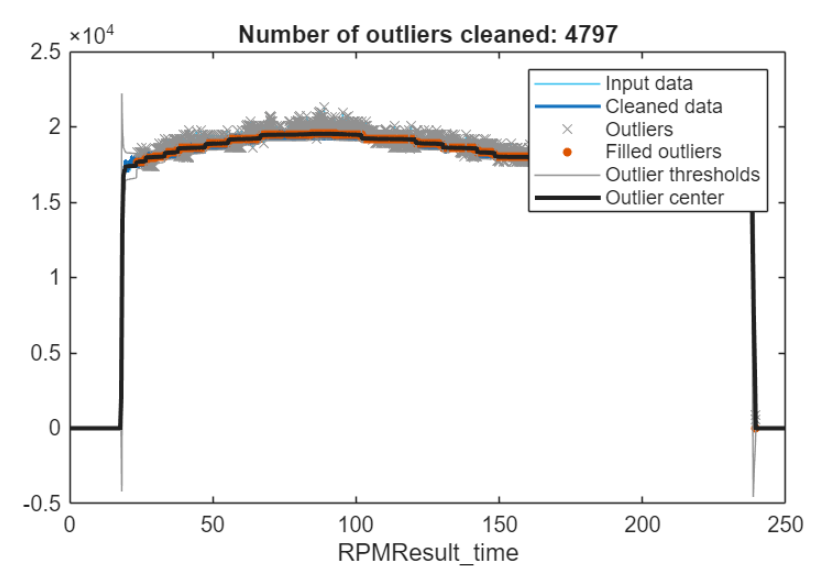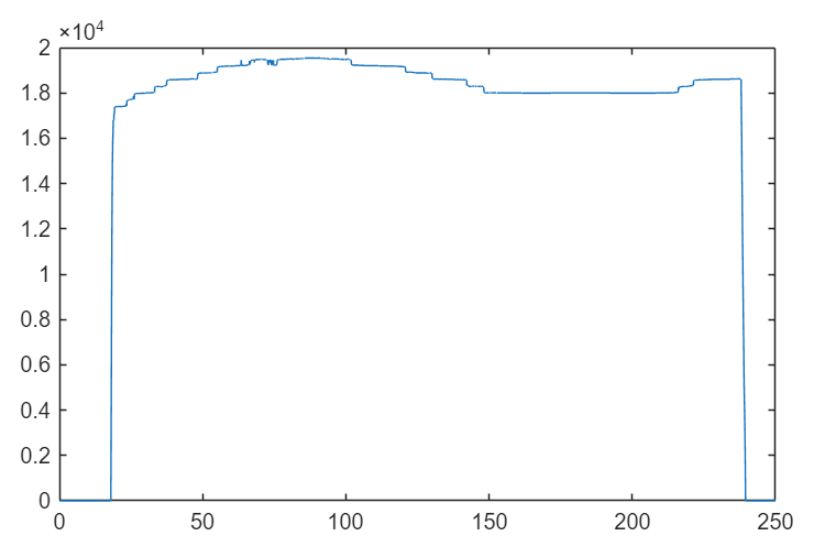

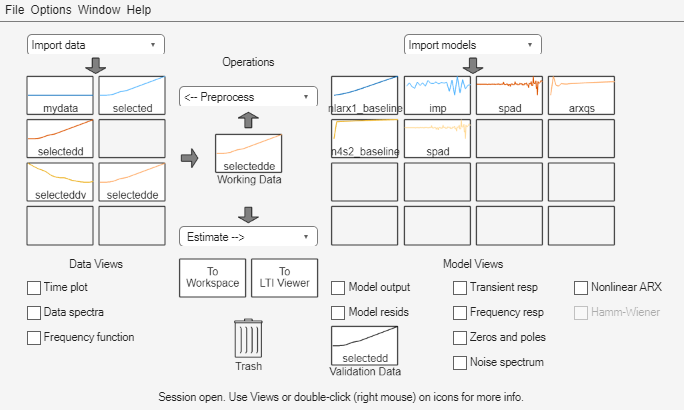

load Baseline_Result.mat
open Data_Cleanup.mlx

plot(RPMResult_time,PWMRequest_Resam_100Hz)
title("Input (PWM)")
plot(RPMResult_time,RPMResult_Clean_func)
title("Output (RPM)")

### Task 11: [Optional] System Identification

- Open "systemIdentification"

systemIdentification

#### Load data

- Load "Time domain data" by using "PWMRequest_Resam_100Hz" and "RPMResult_Clean_func" as an "input" and "output" respectively.

#### Preprocess data

- "**Select Range**" for Select only operating range **select sample [2151 23651] - exclude PWM = 0 region*

- "**Remove means**" for removing overall mean

- "**Select Range**" for Separating data for "**estimation[1:6341]**"  and "**validation[6340:13308]**" 

#### Estimate and Validate

- "**Quick Start**" for quick estimate the model by default method (Imp, Freq, ARX, state space)

 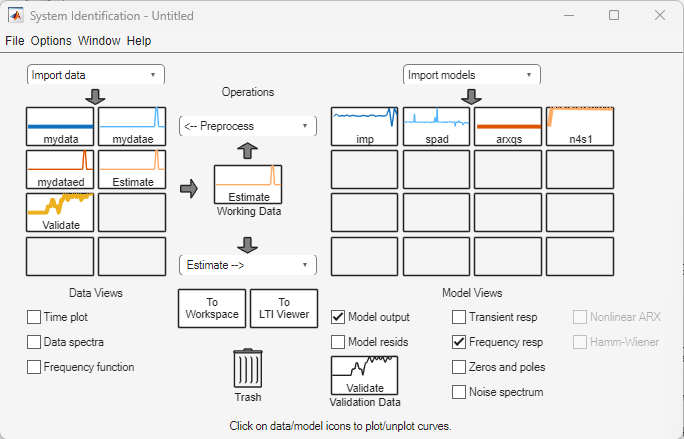

- Check "**Model ouput**" to compare the result with the "**validation data**"

 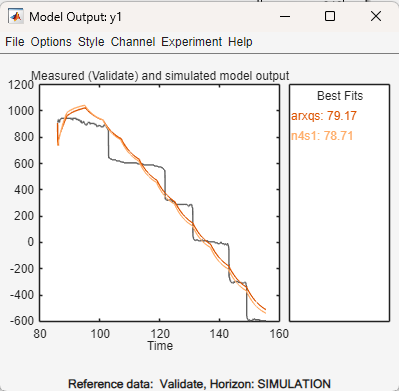

- Double click at model and "**Export**" the model --> Model will appear in MATLAB workspace.

#### Apply model for simulation

- Review predefine session model "**systemiden_data_baseline**"

systemIdentification("systemiden_data_baseline")

- Load predefine model data

load SysIden_Plant_model.mat

- Open predefine plant

 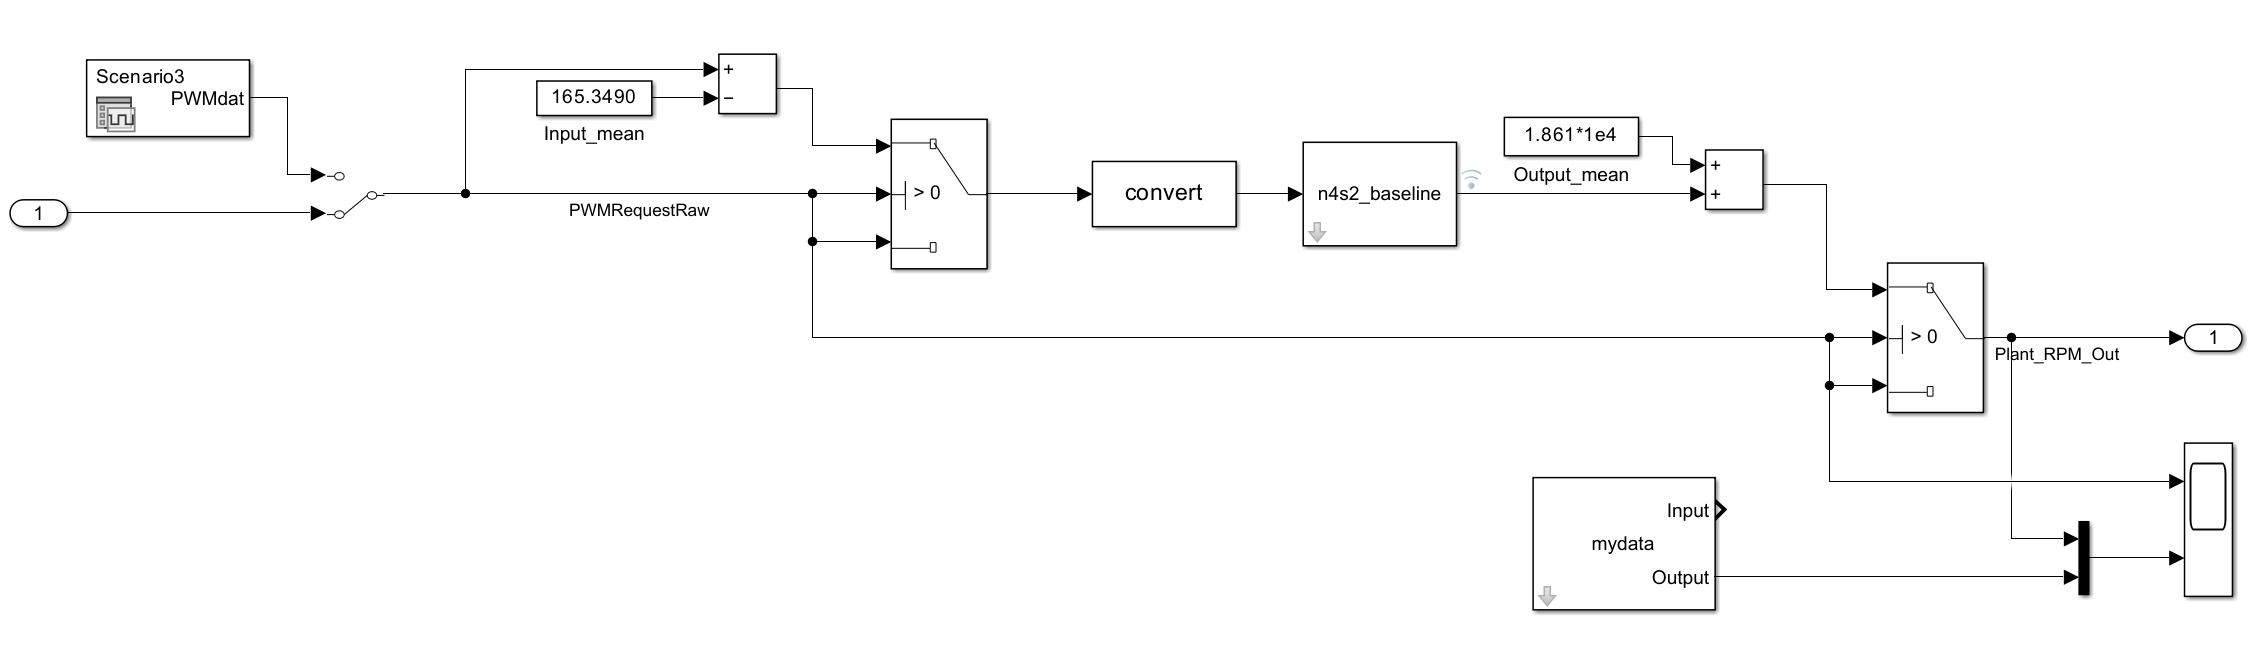

open SysIden_Plant.slx

sim("SysIden_Plant.slx", 250)

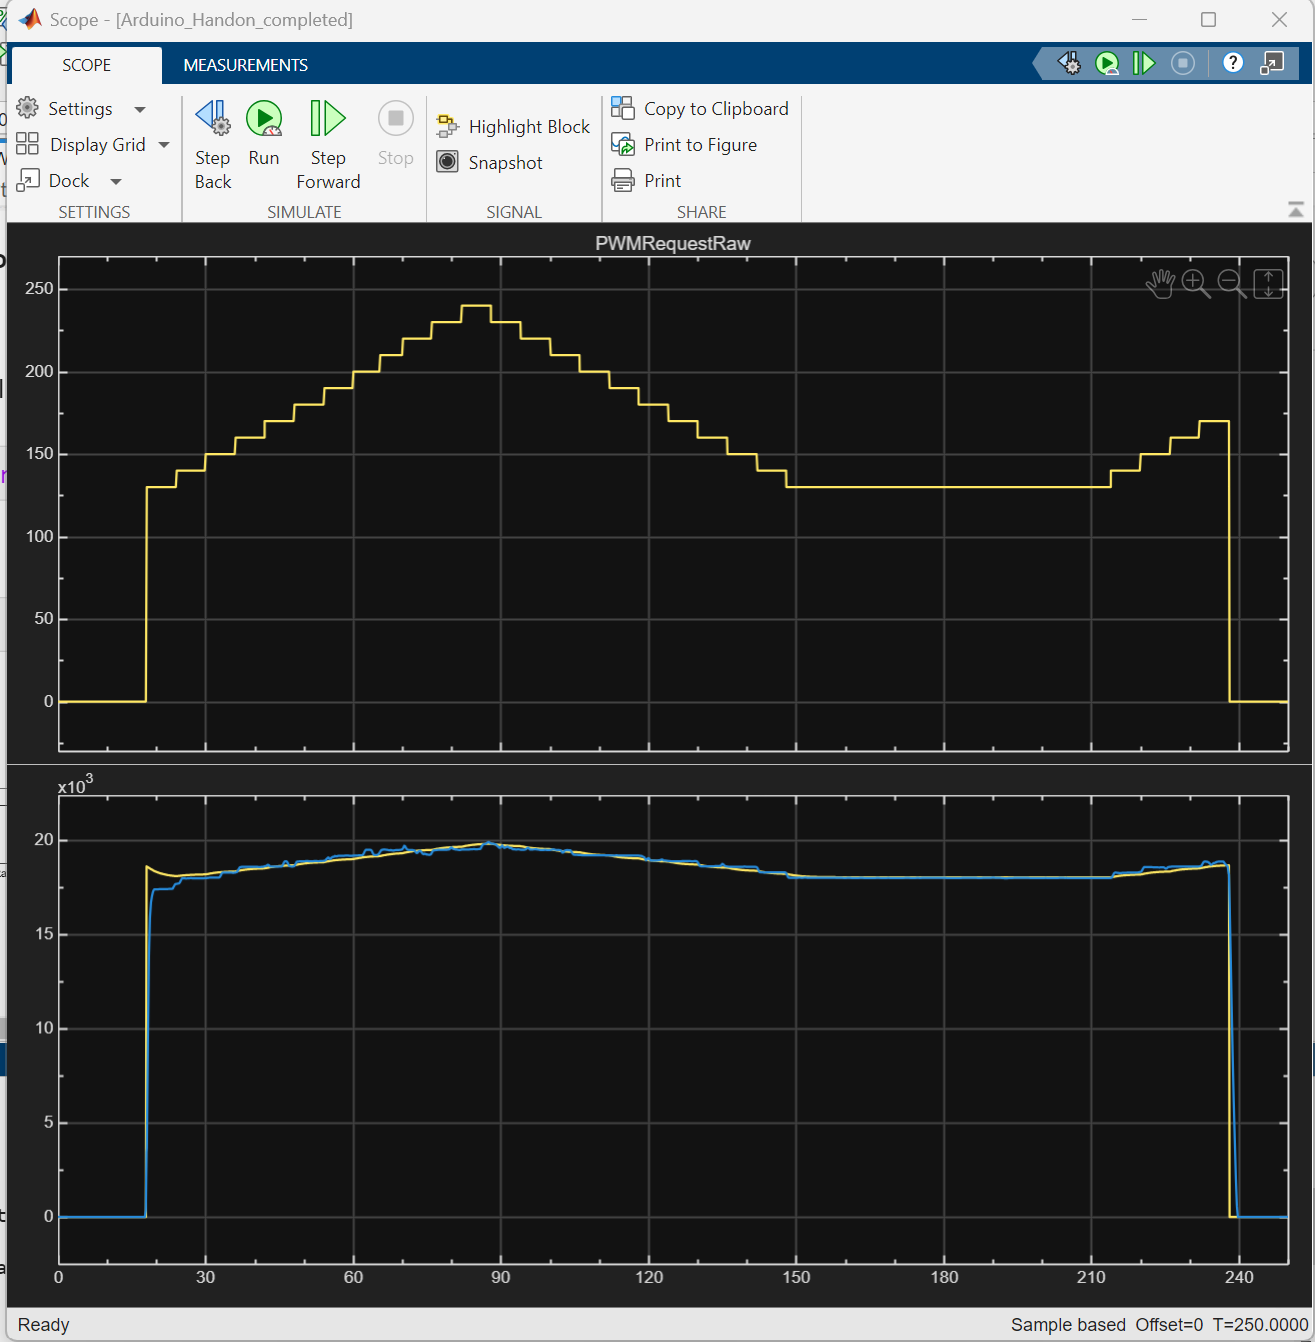

## Simulation close loop Control Tunning with virtual plant [PID Tuner]

### Task 11: Virtual plant close loop control

- Drag and Drop "**Model**" block from "**Simulink>Ports & Subsystems**" to the workspace

- Double click at "Model" block and link to "SysIden_Plant.slx"

 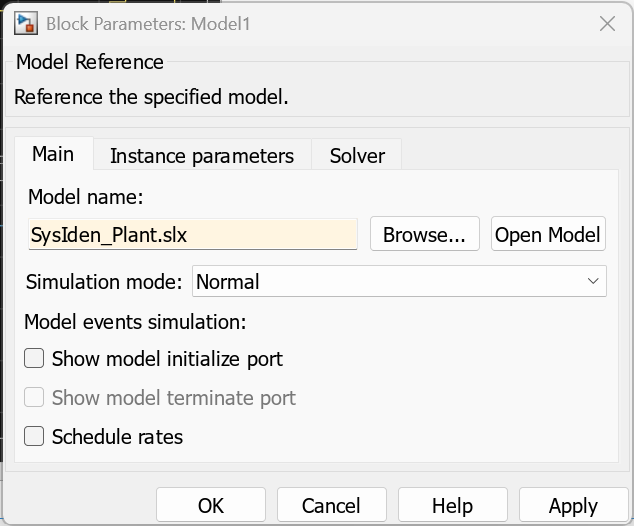

- Connect "**PWMRequest**" to the Plant's "**model**" and Loop back Plant's model output to PID process. **Do not forget to add "****Unit Delay****" in simulation*

- You can add another "**Manual Switch**" for easier switching between "**RPM"** input from "**Tachometer**" or "**Plant's model**" block

 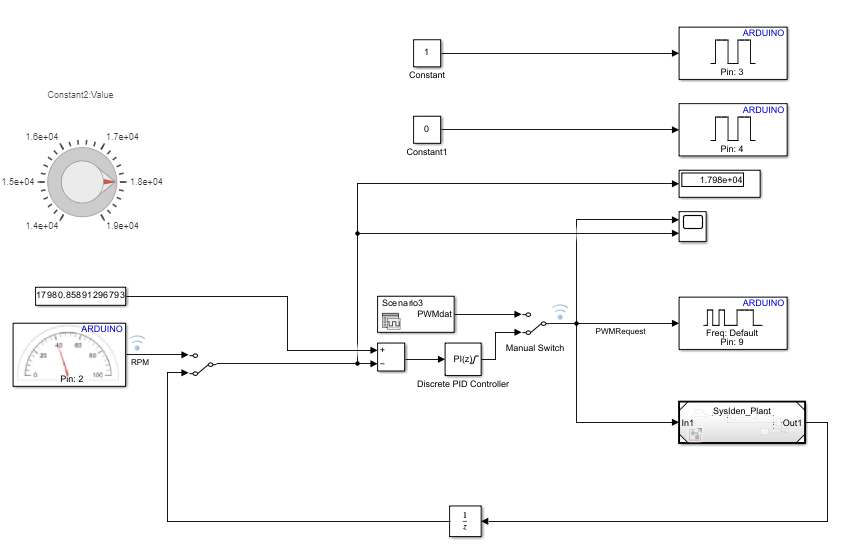

- Start simulate the system by clicking "**Run**" at Simulate section **Try to change the setpoint by varying knob during the simulation to see the response*

- Check the output by double clicking at "**Scope**"

 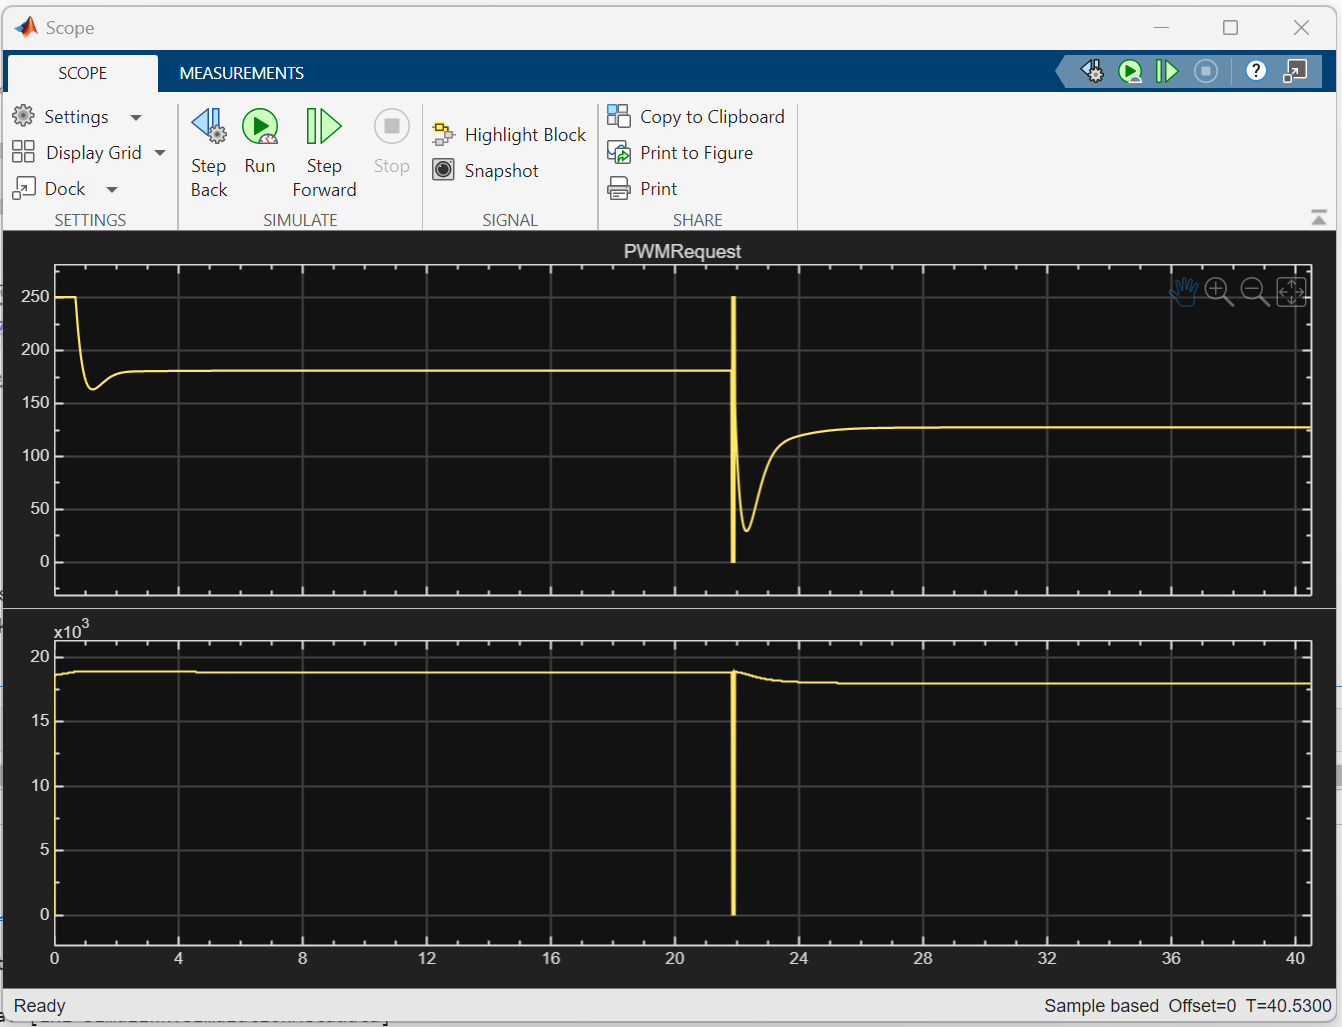

### Task 12: Tunning Controller with PID tunner

- Double click at "**Discrete PID Controller**" --> Click "**Tune**" button

 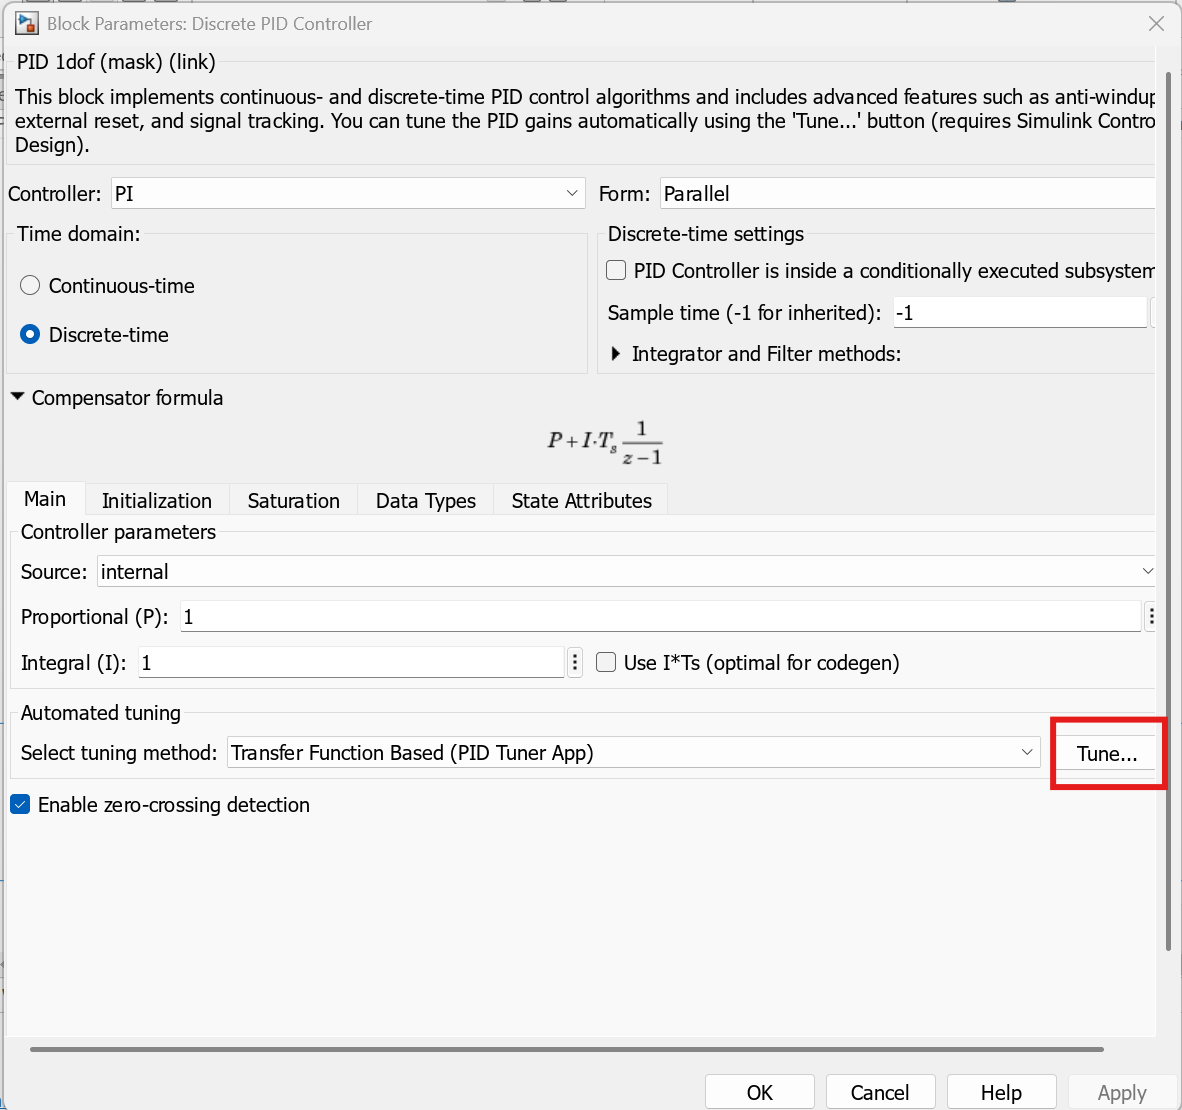

- PID tuner window will pop-up. You can try to tune your controller's "**Response time**" and "**Transient Behavior**" by sliding the bar in picture below --> Click "**Update Block**" after you finished

 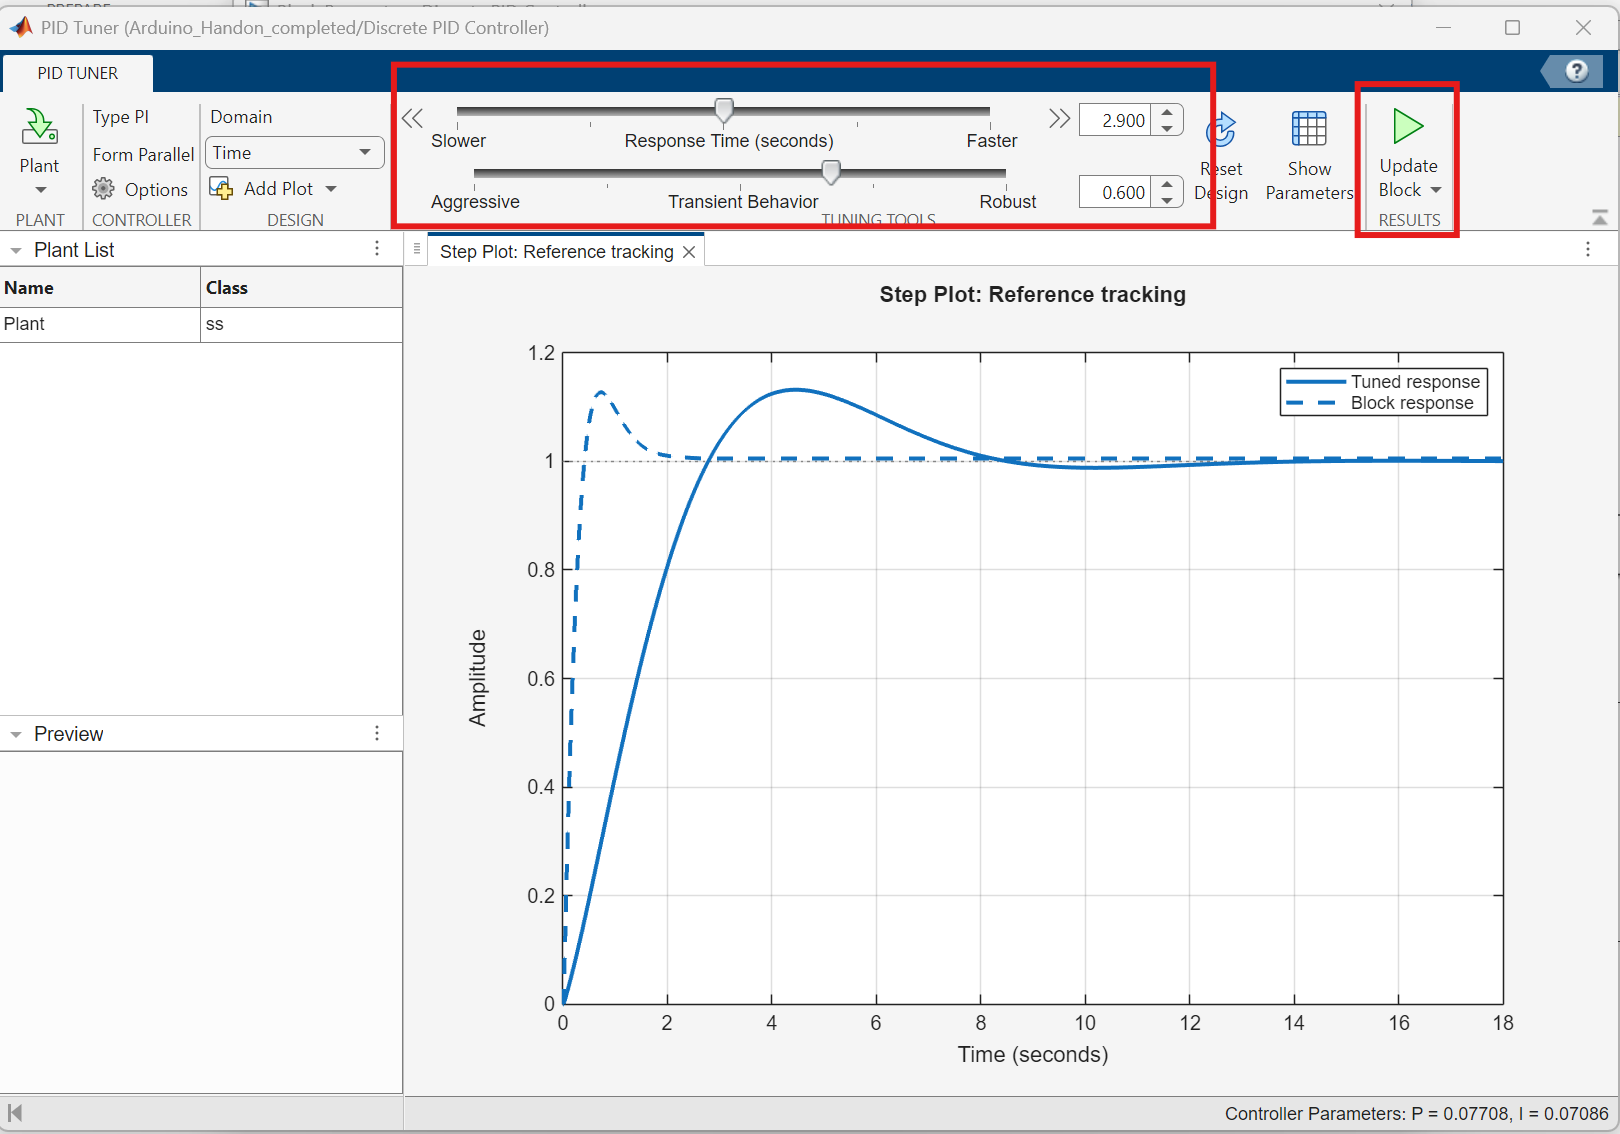

- Try to "**Run**" simulation again to see the chage after you tunning

 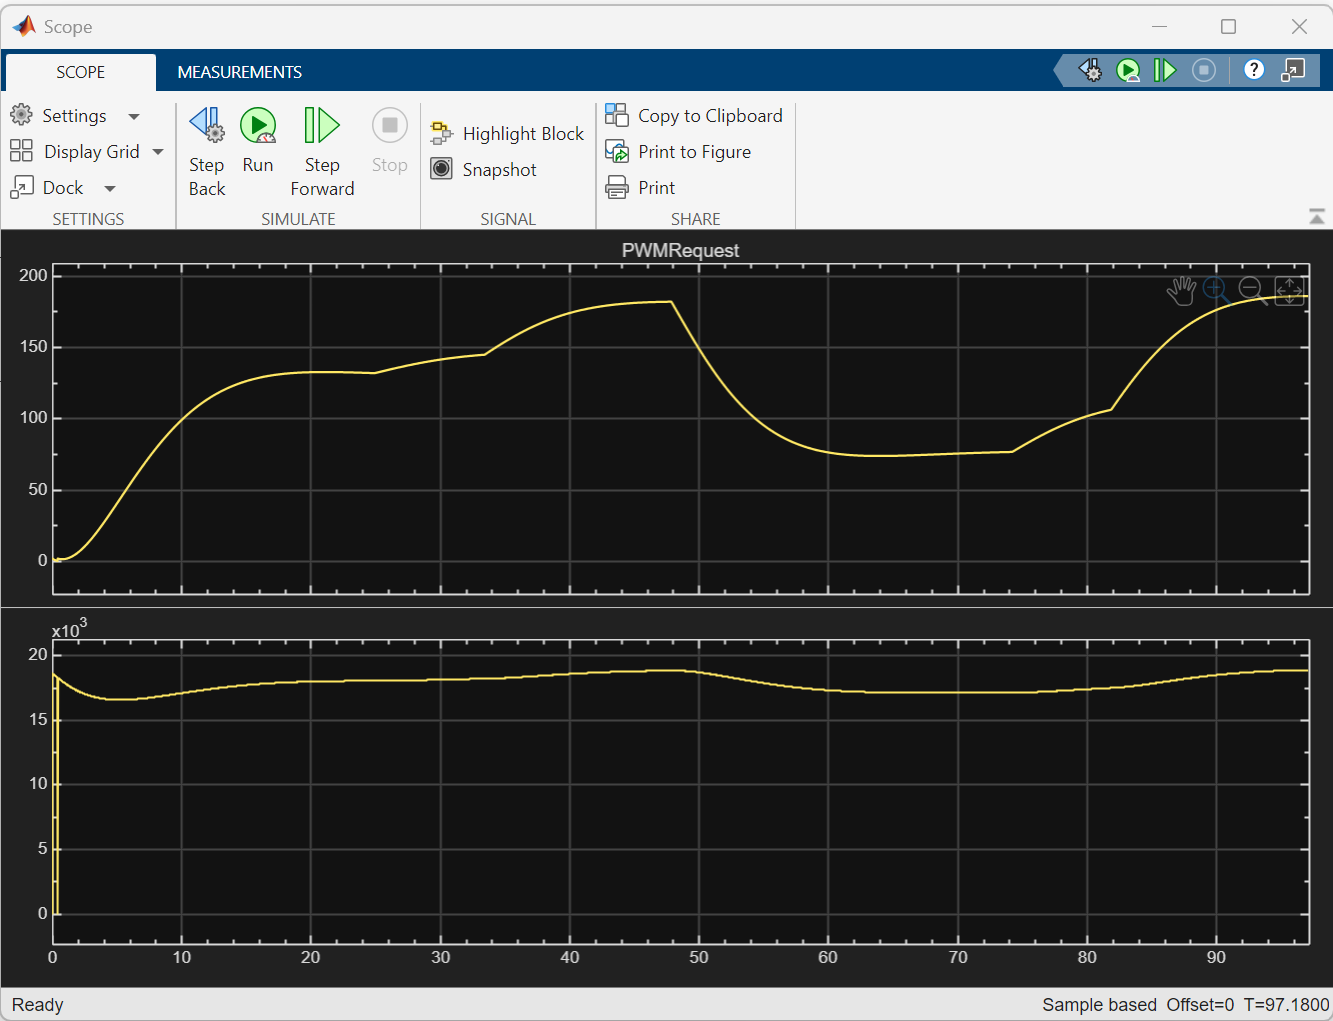

open Arduino_Handon_completed.slx